# 拡張GFTによるDiGraphフィルターの実現

2023年11月12日

村松正吾，北村帆高（新潟大学）

#### 参考文献:

- H. Kitamura, H. Yasuda, Y. Tanaka and S. Muramatsu, "Realization of DiGraph Filters Via Augmented GFT," 2023 IEEE International Conference on Image Processing (ICIP), Kuala Lumpur, Malaysia, 2023, pp. 2885-2889, doi: 10.1109/ICIP49359.2023.10222618.

- Abstract: This study proposes a filtering method for directed graph (digraph) signals. In order to realize digraph filtering, a novel graph Fourier transform (GFT), – Augmented GFT (AuGFT) –, is proposed by defining an Hermitian adjacency matrix. Although there has been the same method to give the adjacency matrix of digraphs, this study defines a novel digraph Laplacian. The existing digraph Laplacian does not give the graph signal variation considering the edge directions, while the novel one does. This paper introduces three important ideas. The first is the definition of a novel degree matrix to give the novel digraph Laplacian. The second is to decompose the symmetric and skew-symmetric components of the novel digraph Laplacian independently into their spectral components. The third is, based on the decomposition, to augment the conventional GFT for digraphs as an invertible real-valued dictionary. The new GFT is shown to provide a practical form of real-valued digraph filtering. The significance of the proposed method is verified through simulations of signal filtering on digraphs.

- URL: [https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=10222618&isnumber=10221892](https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=10222618&isnumber=10221892)

**謝辞：**

- 本研究は[科研費21H04596](https://kaken.nii.ac.jp/ja/grant/KAKENHI-PROJECT-21H04596/)および[科研費22H00512](https://kaken.nii.ac.jp/ja/grant/KAKENHI-PROJECT-22H09512/)助成による。

## 各種設定

isDiGraph = true; % 有向グラフとして解析
isRiver = true; % 河川データを解析

if ~exist('./gspbox','dir')
    setup
else
    addpath('gspbox')
end
gsp_start

GSPBox version 0.7.5. Copyright 2013-2015 LTS2-EPFL,
by Nathanael Perraudin, Johan Paratte, David Shuman and Vassilis Kalofolias


RESULTS_DIR = "../results/";
FIGEXT = ".png";

## 有向グラフの隣接行列 $\mathbf{A}$ の生成

有向グラフ $\mathcal{G}$ の定義

if ~isRiver
    s = [1 1 2 2 3 3 4 4 4 5];
    t = [2 3 4 5 6 7 8 9 10 4];
    G = digraph(s,t)

有向非巡回性の確認

    isdag(G)

有向グラフ $\mathcal{G}$ のエッジ $\mathcal{E}$

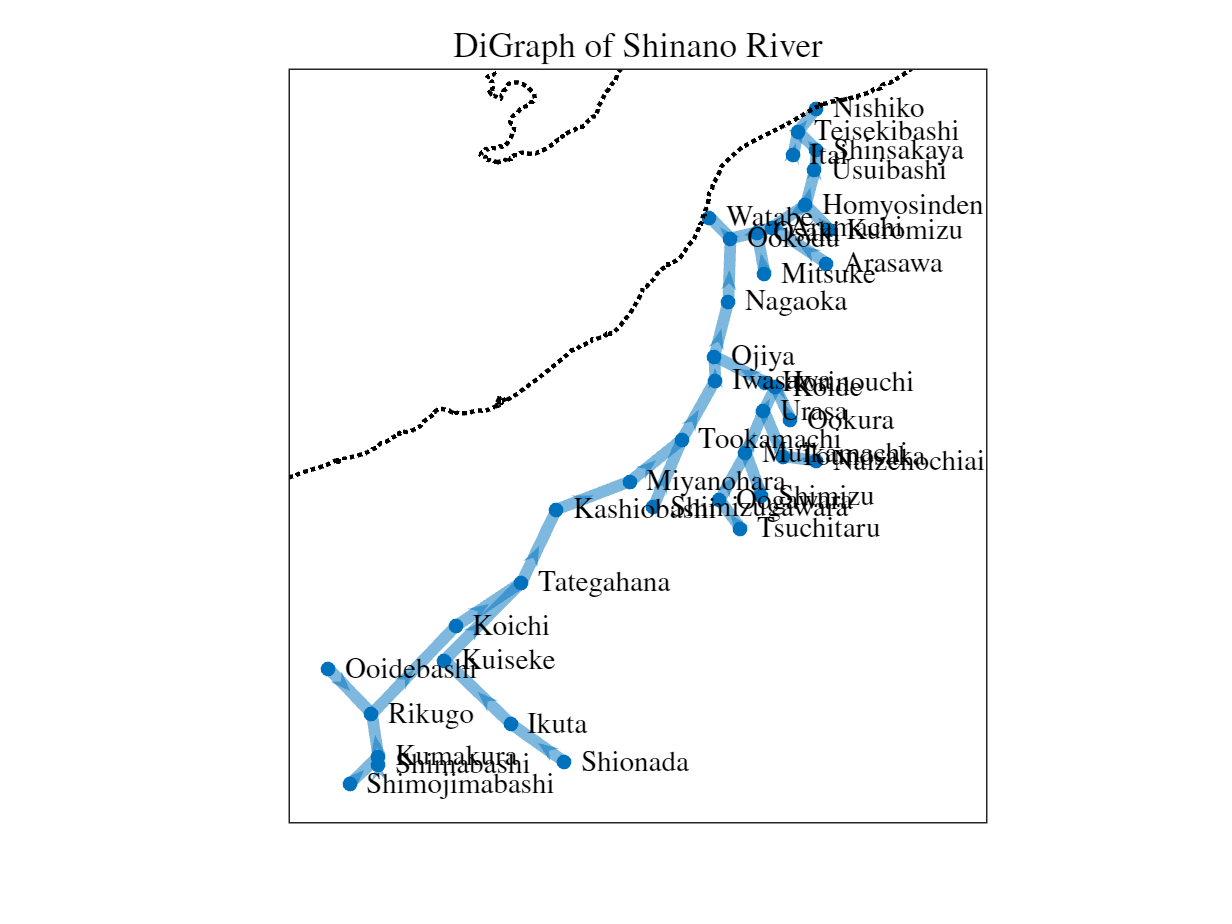

    G.Edges

有向グラフ $\mathcal{G}$ のノード $\mathcal{V}$ 

    G.Nodes

## 有向グラフ $\mathcal{G}$の描画

    A = full(adjacency(G,'weighted'))

U =     0.0488    0.0441   -0.0093   -0.0053   -0.2644    0.0573   -0.0282    0.1100   -0.0568    0.0058   -0.1326    0.0060   -0.1411   -0.0000   -0.0000    0.0000    0.0057   -0.0029    0.0076   -0.0288   -0.0534    0.0975    0.0426    0.0406   -0.2572   -0.0697   -0.4987   -0.0175    0.0079   -0.0006    0.2923   -0.2052   -0.1466    0.0385   -0.2174   -0.1950   -0.0061    0.0072   -0.1529   -0.5221
    0.0662    0.0661   -0.0218   -0.0035   -0.2443    0.0625   -0.0847   -0.1114    0.0116    0.0021   -0.1372    0.0121    0.1403    0.0000   -0.0000    0.0000    0.0007   -0.0174    0.0019   -0.0107   -0.0201    0.0408    0.0215    0.0443   -0.3801   -0.0209   -0.3734   -0.0464    0.0902    0.0047   -0.4084    0.0359   -0.0719    0.1869   -0.0599   -0.1522   -0.2108   -0.0180    0.1711    0.5102
    0.0917    0.0960   -0.0368   -0.0017   -0.1776    0.0505   -0.0960   -0.2357    0.0669   -0.0051    0.1480   -0.0102   -0.0596   -0.0000   -0.0000   -0.0000    0.0001   -0.1038    0.0003   -

Q =     0.4472   -0.0008    0.0000   -0.4372   -0.0293   -0.0005    0.0209   -0.0004   -0.3074    0.0000    0.2112    0.0036    0.0558    0.0091    0.2074   -0.0020   -0.2897    0.0011    0.0927   -0.0045   -0.2922   -0.0016   -0.1134   -0.0485   -0.0244    0.0022   -0.0683    0.0076   -0.0000    0.4297    0.0117    0.0017    0.1894   -0.0553
    0.0007    0.4014    0.4905    0.0000    0.0007   -0.0374    0.0046    0.2172   -0.0000   -0.0616   -0.0038    0.2213    0.0428   -0.2616   -0.0018   -0.1816   -0.0002   -0.0462    0.0023    0.0477    0.0015   -0.2679    0.1257   -0.2944    0.0248    0.2751    0.0068    0.0614    0.2264    0.0000    0.0126   -0.0843   -0.0774   -0.2653
   -0.3093    0.0006   -0.0000    0.4341    0.0355    0.0007   -0.3174    0.0067   -0.2218    0.0000   -0.0696   -0.0012    0.3334    0.0546    0.3783   -0.0037   -0.2610    0.0010    0.0734   -0.0036   -0.2333   -0.0013   -0.1289   -0.0550    0.0566   -0.0051   -0.0180    0.0020   -0.0000    0.1873   -0.1324   -

C =    0.0000 + 0.0000i   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.5000 + 0.5000i   0.0000 + 0.0000i   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.00

D =     2.1213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    2.1213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    2.1213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

L =    2.1213 + 0.0000i  -0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.5000 - 0.5000i   2.1213 + 0.0000i  -0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.00

Lmd =     0.3534         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.3537         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3546         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

Sgm =          0    1.1583         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -1.1583         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    1.1129         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

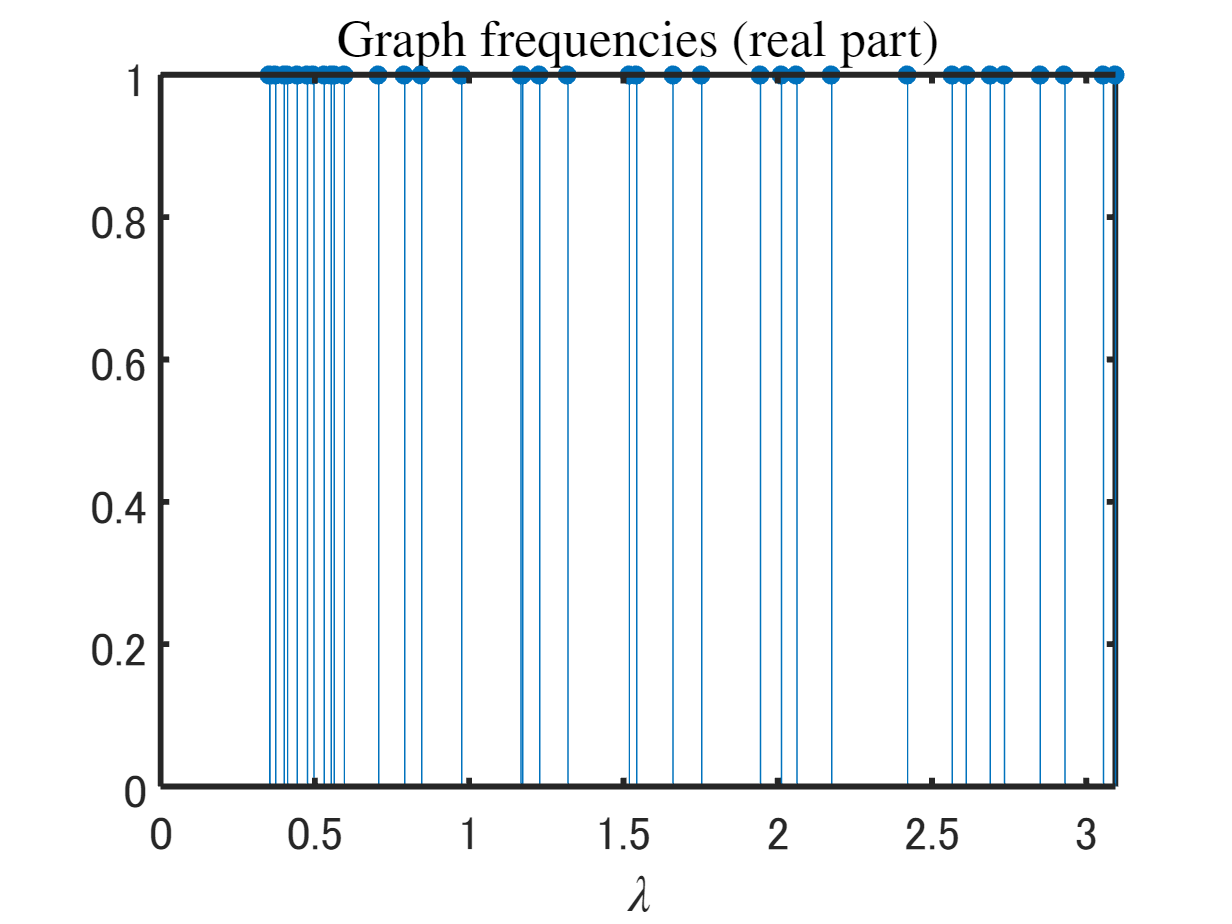

else
    Ariver = [
        0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...  %尾崎1
        1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...  %荒町2
        0 1 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...  %保明新田3
        0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...  %臼井橋4
        0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...  %新酒屋5
        0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...  %帝石橋6
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...  %西港7
        1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ... %見附8
        0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%板井9
        0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%荒沢10

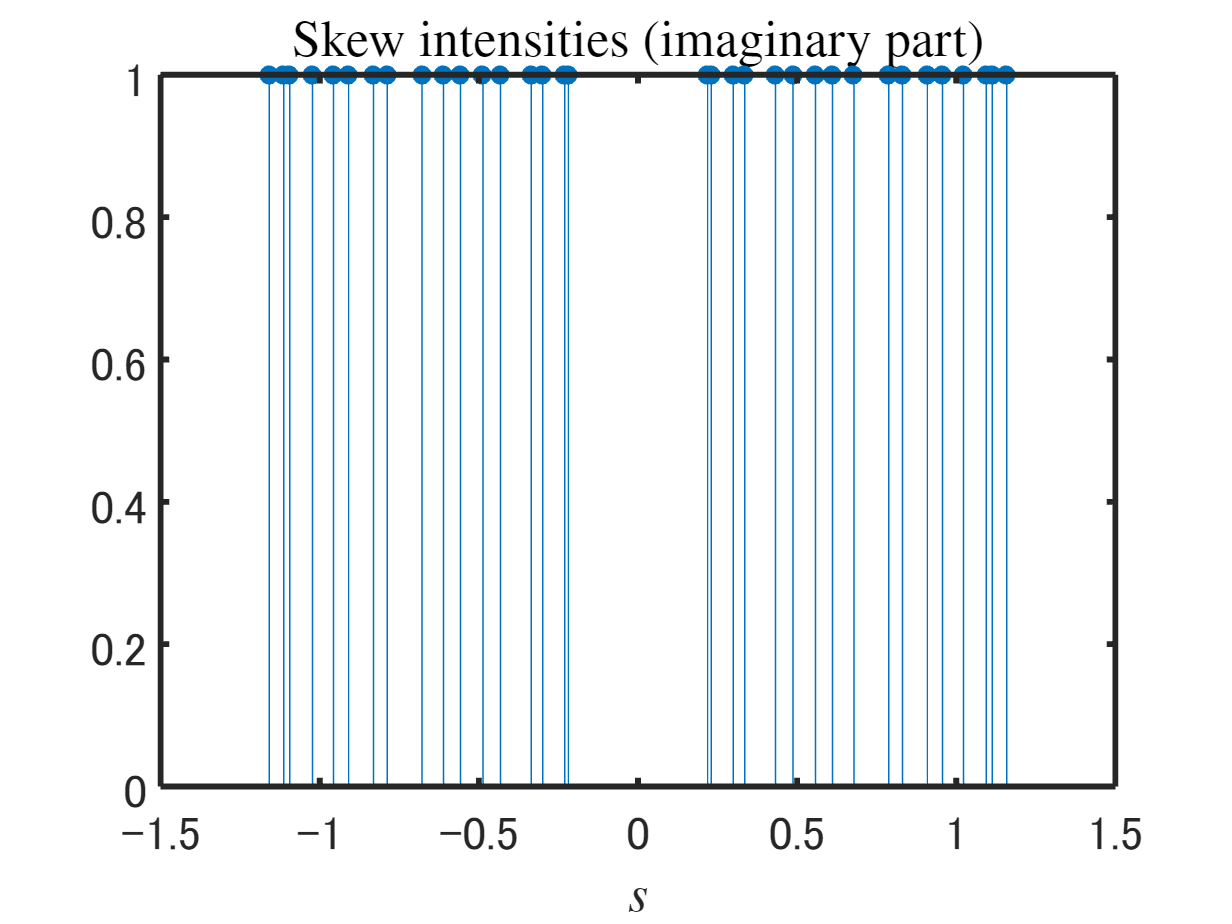

        0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%黒水11
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%渡部12
        0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%大河津13
        0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%長岡14
        0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%小千谷15
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%岩沢16
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%十日町17
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%宮野原18
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%堀之内19
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%小出20
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%浦佐21
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%六日町22
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%大倉23
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%清水24

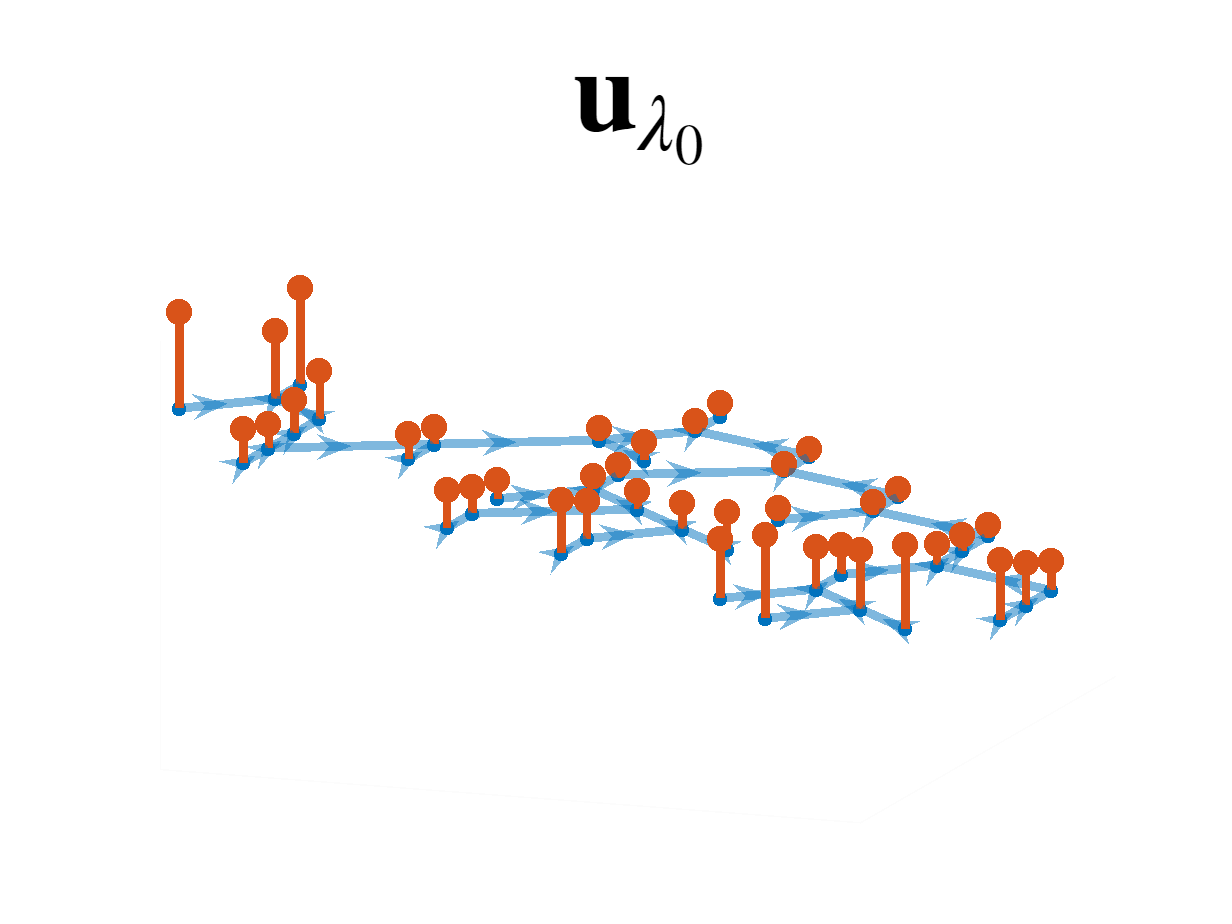

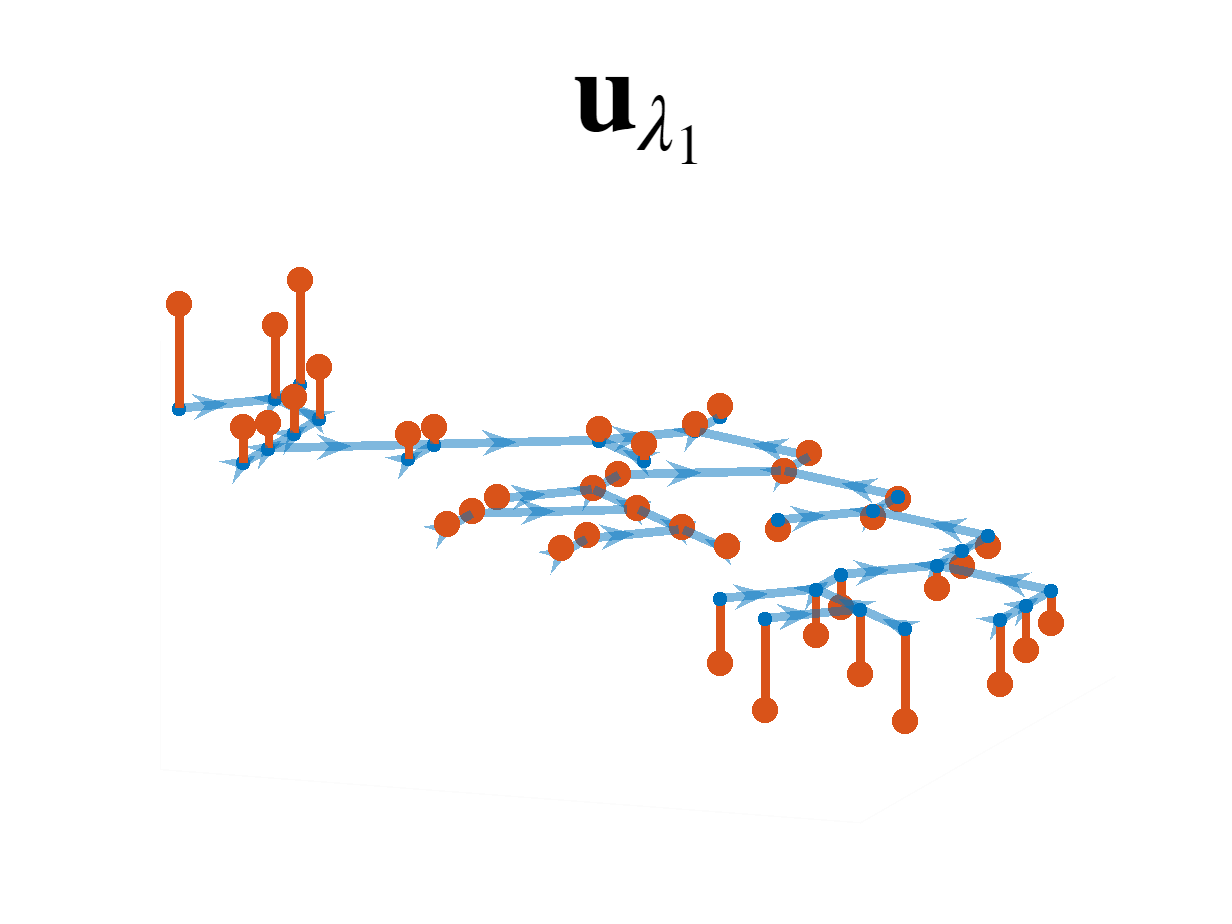

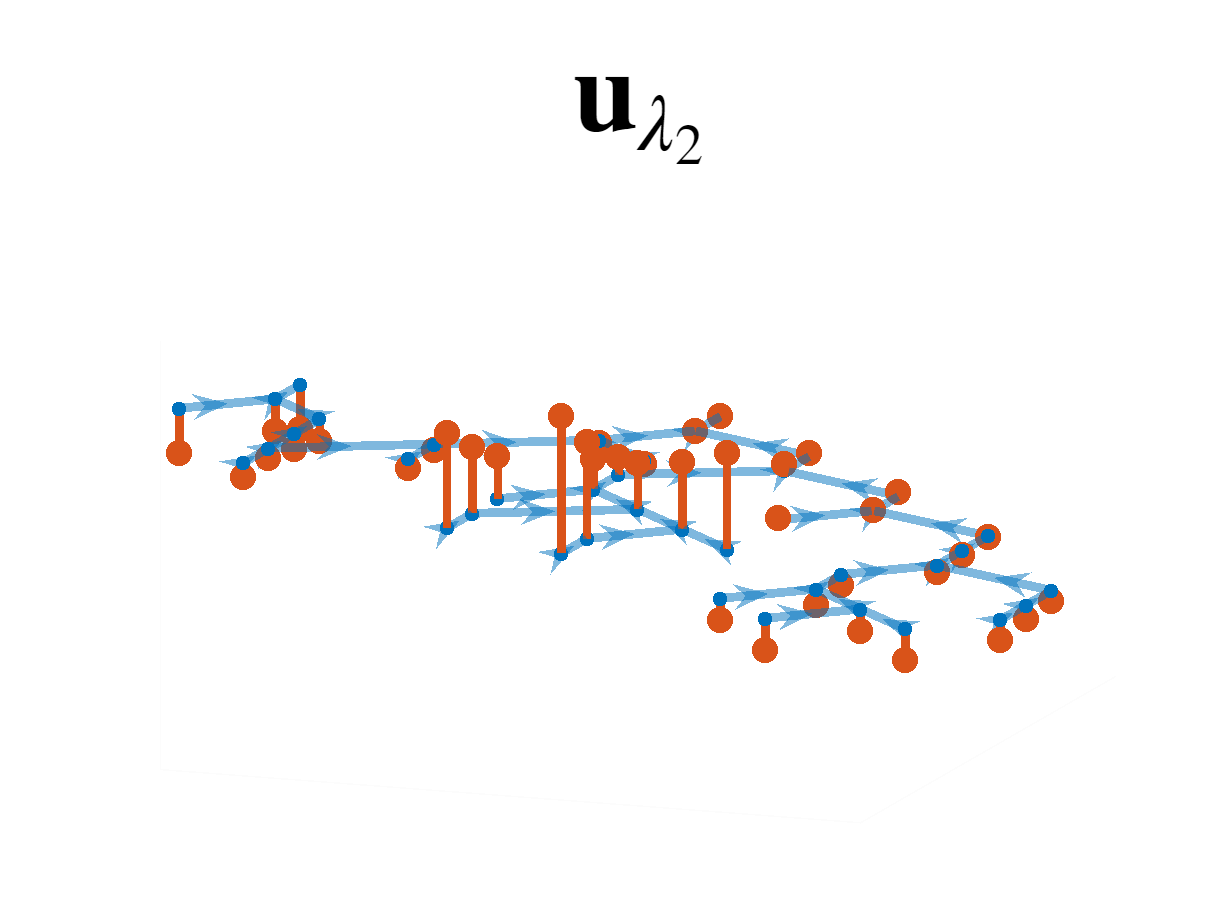

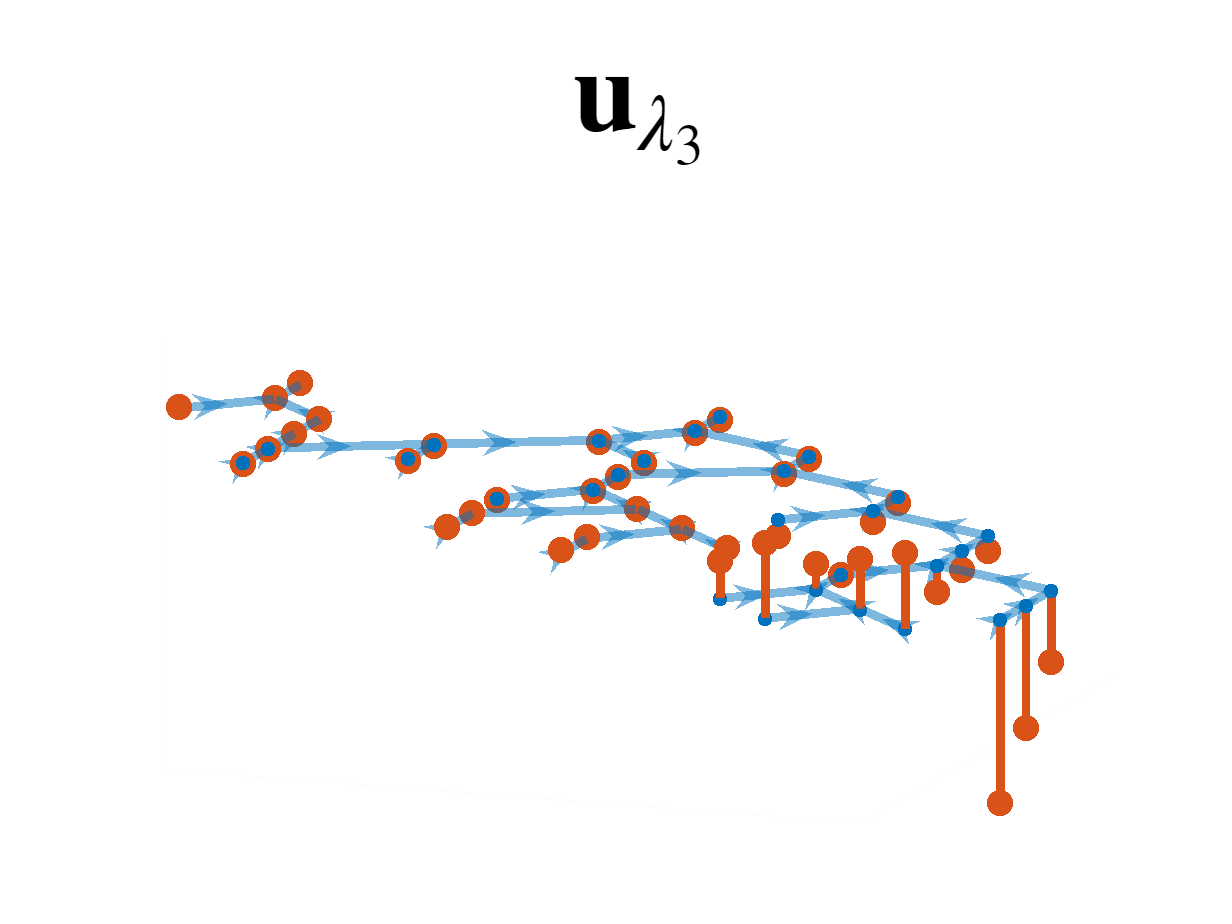

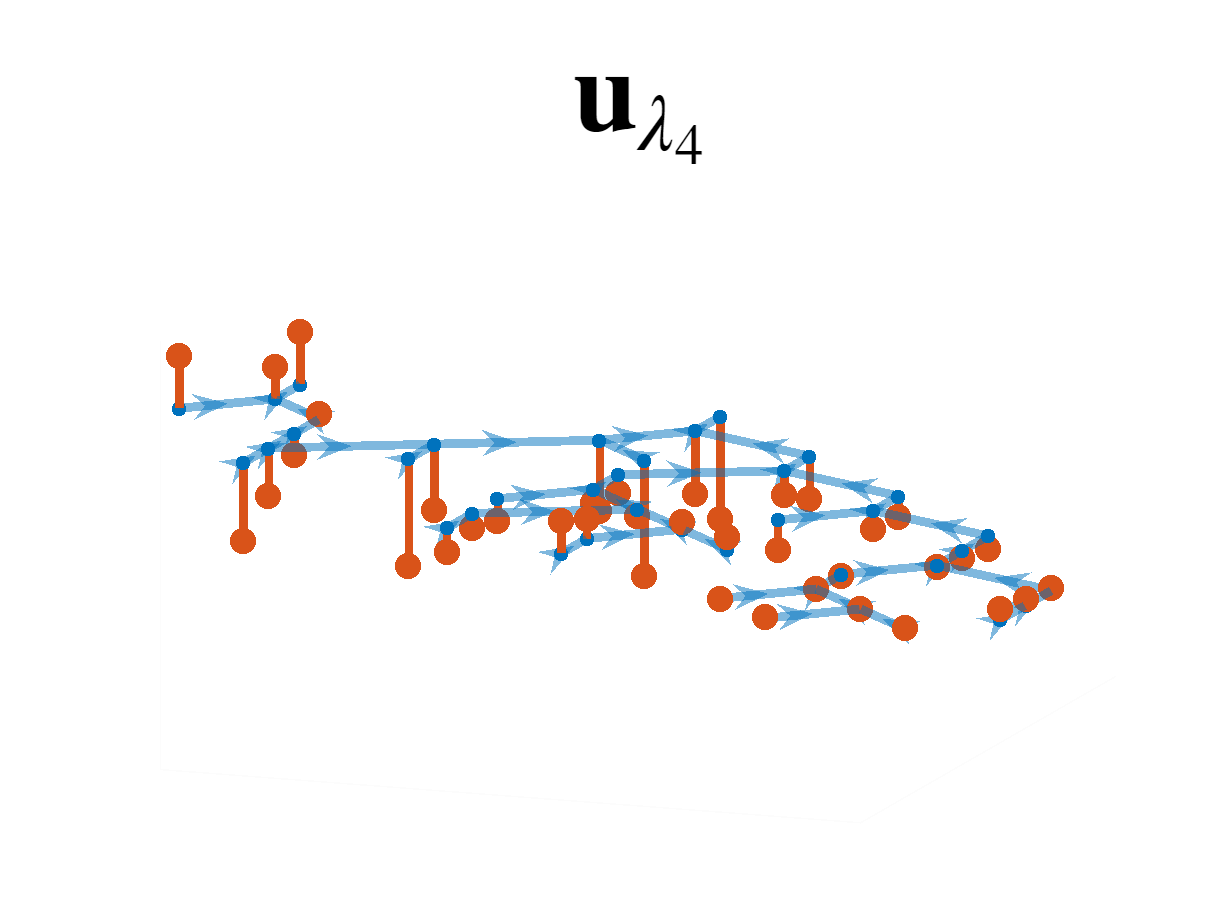

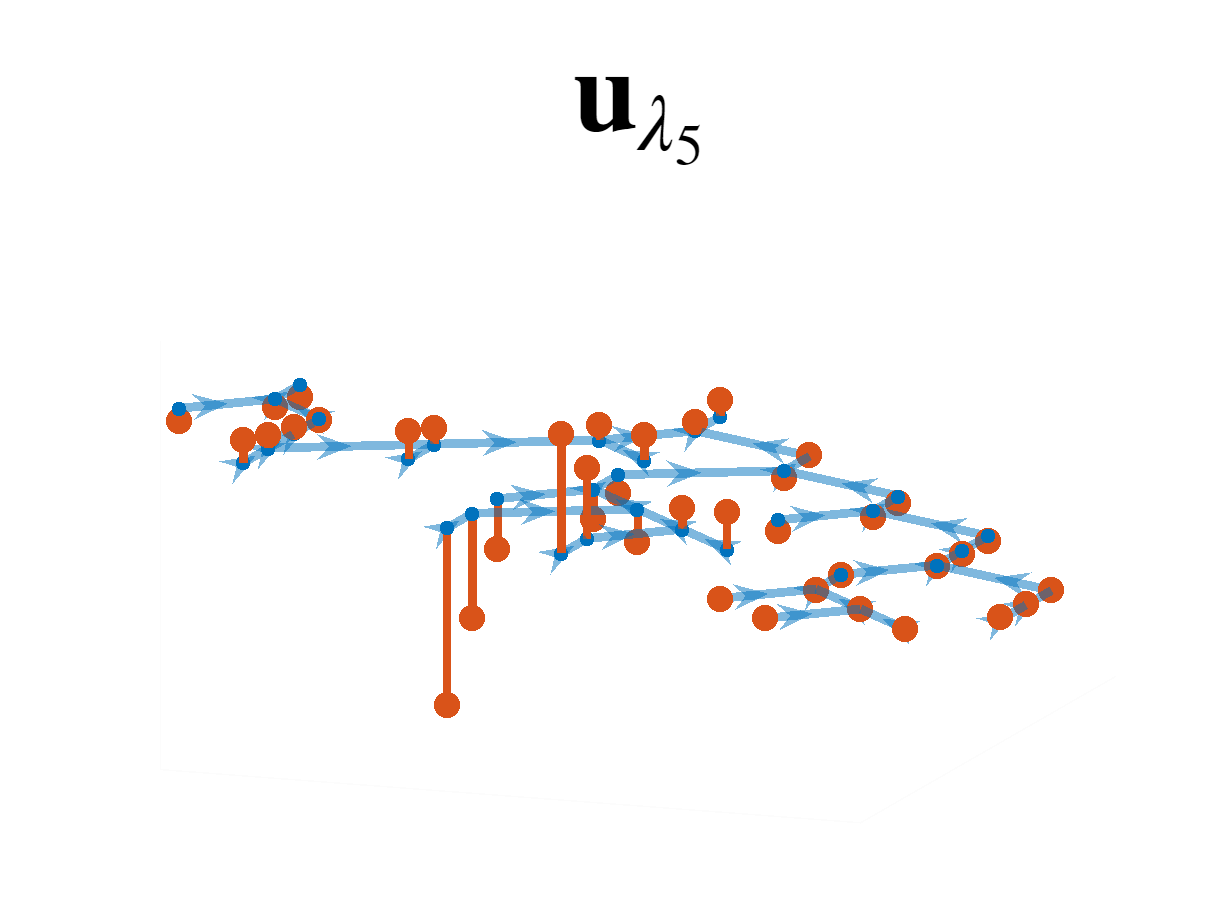

        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%大河原25
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%清水川原26
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%土樽27
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0; ...%塩名田28
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0; ...%生田29
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0; ...%杭瀬下30
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0; ...%立ヶ花31
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%柏尾橋32
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0; ...%下島橋33
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0; ...%熊倉34
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0; ...%陸郷35
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0; ...%小市36
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0; ...%島橋37
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0; ...%内膳落合38
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...%当ノ坂39
        0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0; ...%大出橋40
        ];
    Triver = {'尾崎','荒町','保明新田','臼井橋','新酒屋',...
        '帝石橋','西港','見附','板井','荒沢',...
        '黒水','渡部','大河津','長岡','小千谷',...
        '岩沢','十日町','宮野原','堀之内','小出',...
        '浦佐','六日町','大倉','清水','大河原',...
        '清水川原','土樽','塩名田','生田','杭瀬下',...
        '立ヶ花','柏尾橋','下島橋','熊倉','陸郷',...
        '小市','島橋','内膳落合','当ノ坂','大出橋'};

    TriverEng = {'Osaki','Aramachi','Homyosinden','Usuibashi','Shinsakaya',...
        'Teisekibashi','Nishiko','Mitsuke','Itai','Arasawa',...
        'Kuromizu','Watabe','Ookodu','Nagaoka','Ojiya',...
        'Iwasawa','Tookamachi','Miyanohara','Horinouchi','Koide',...
        'Urasa','Muikamachi','Ookura','Shimizu','Oogawara',...
        'Shimizugawara','Tsuchitaru','Shionada','Ikuta','Kuiseke',...
        'Tategahana','Kashiobashi','Shimojimabashi','Kumakura','Rikugo',...
        'Koichi','Shimabashi','Naizenochiai','Tounosaka','Ooidebashi'};


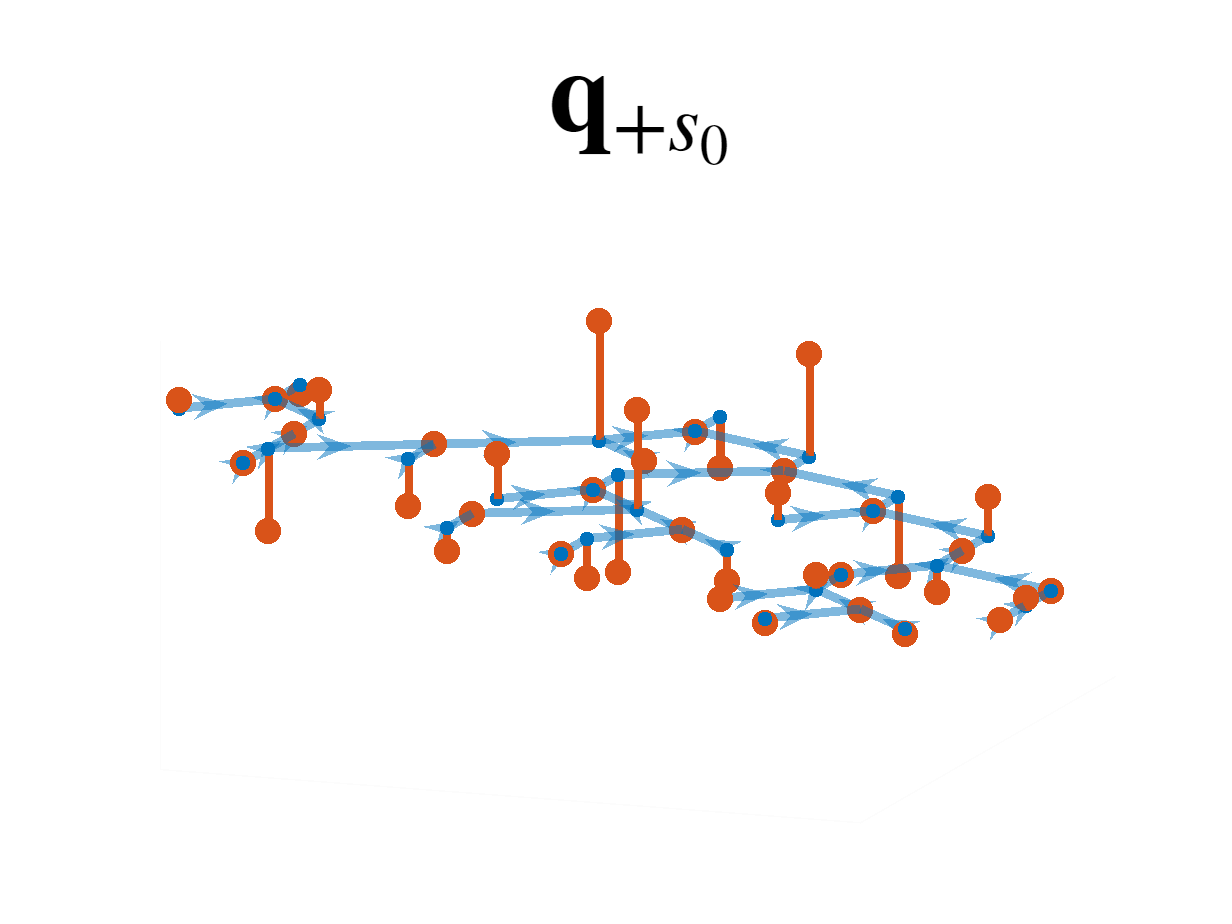

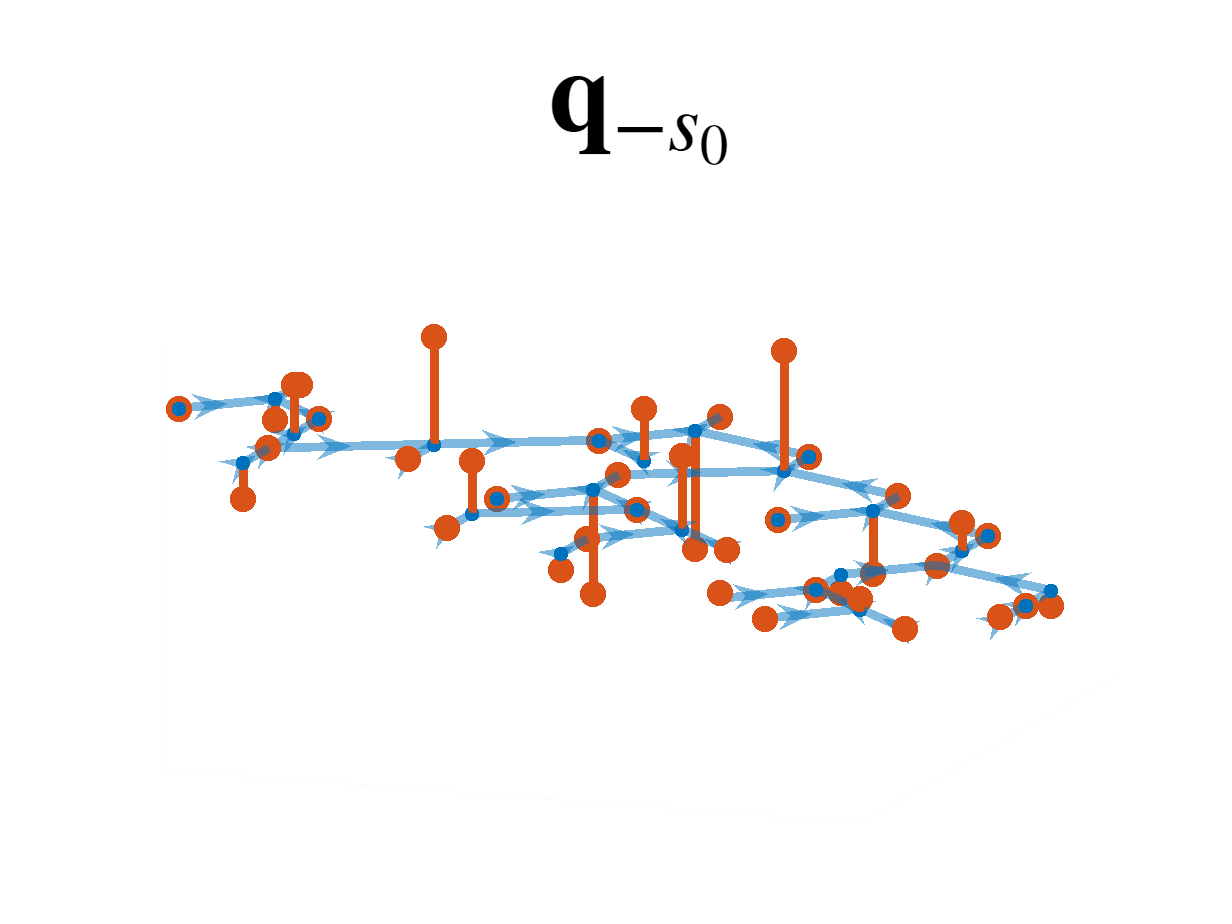

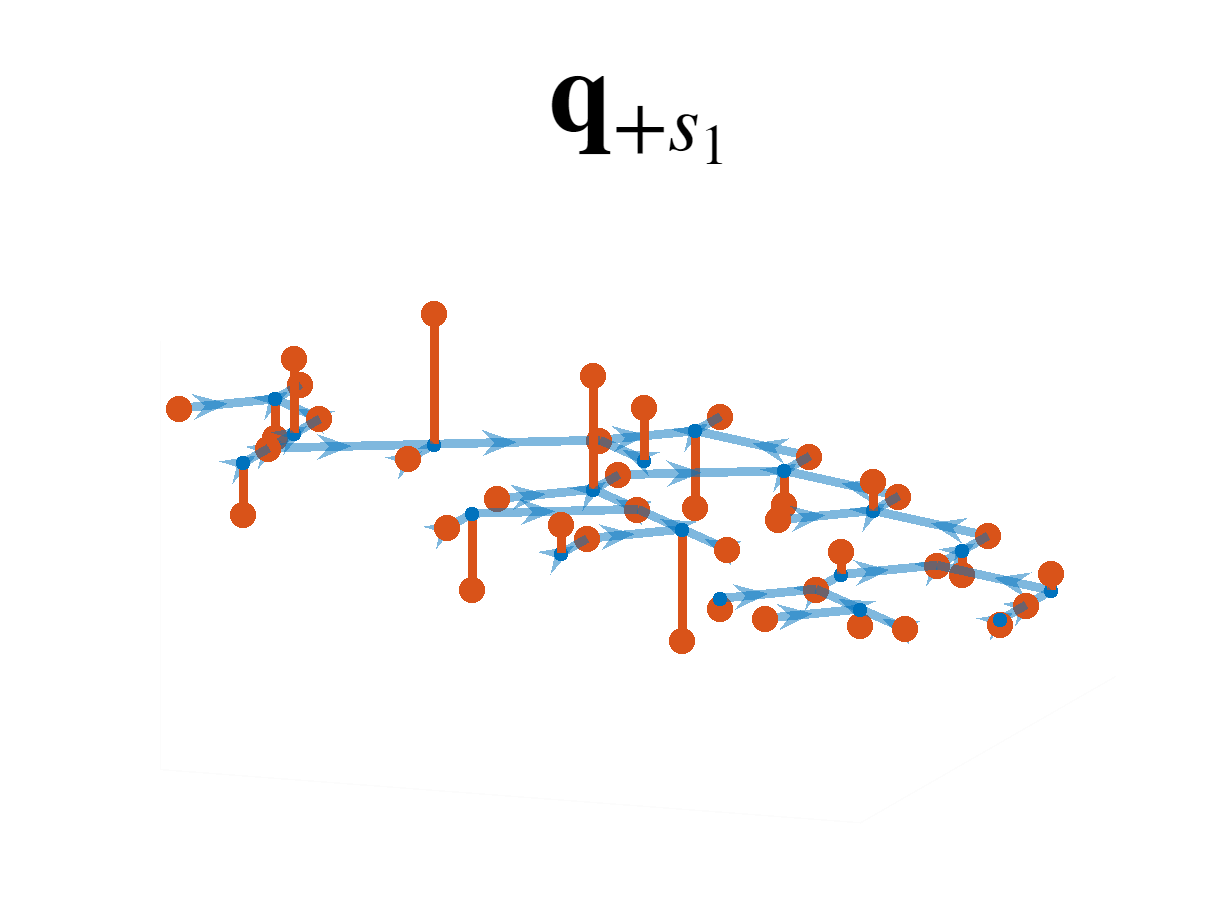

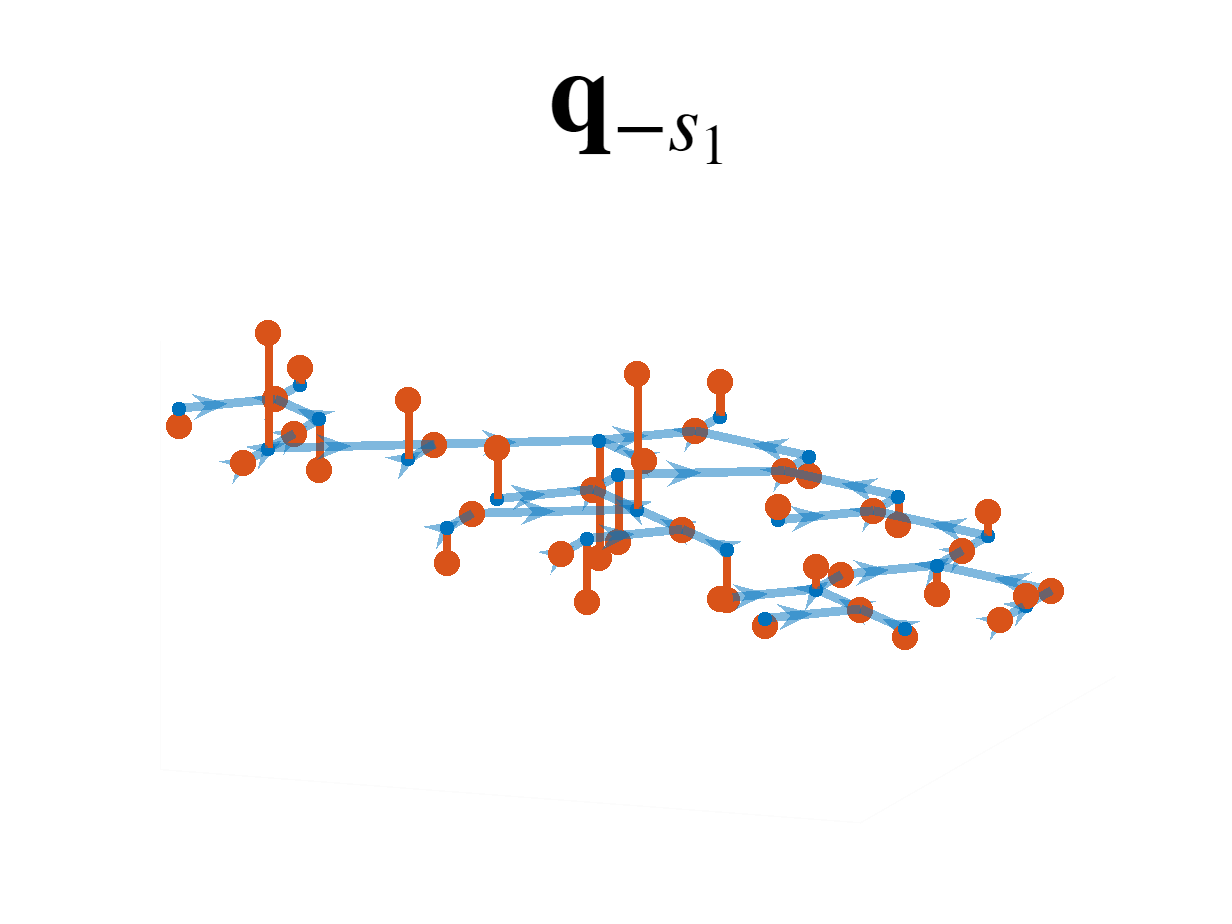

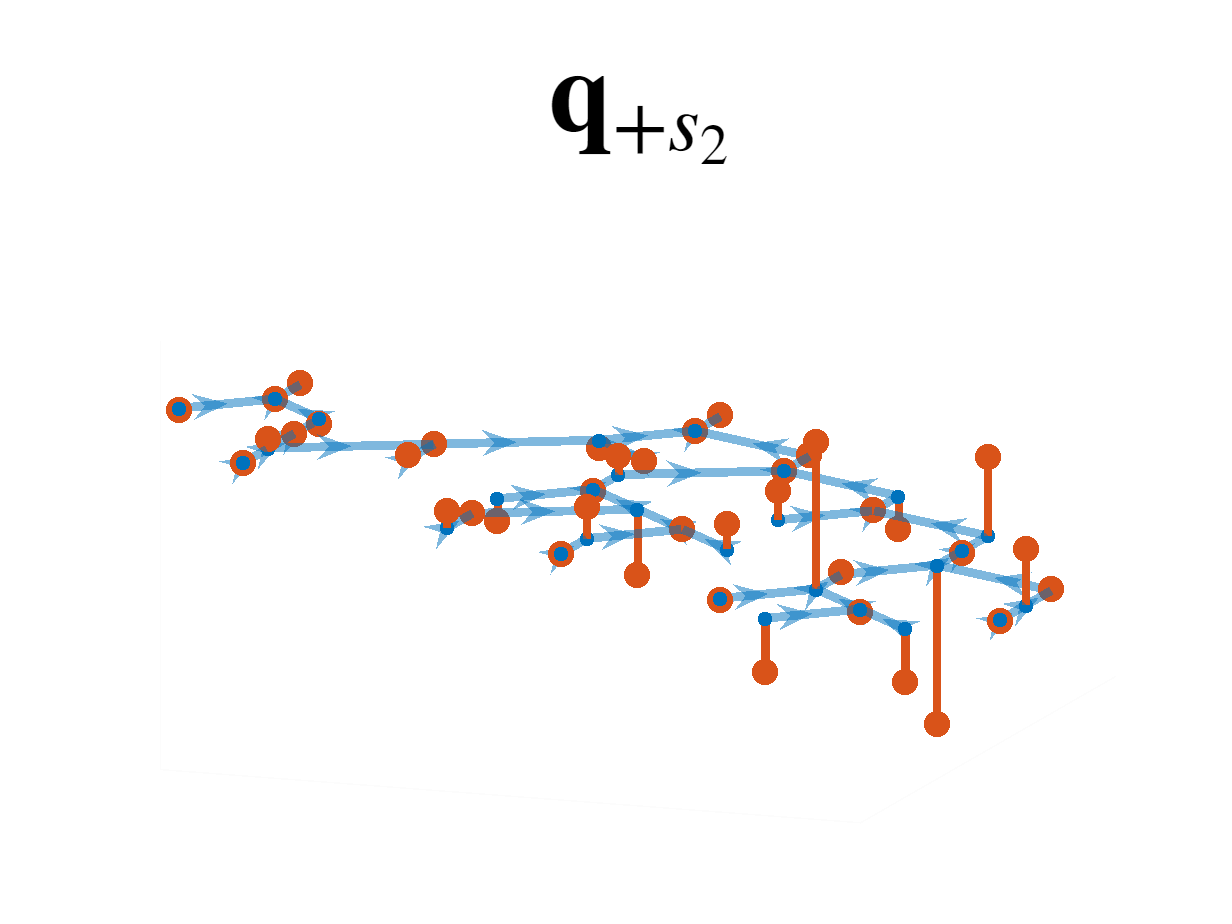

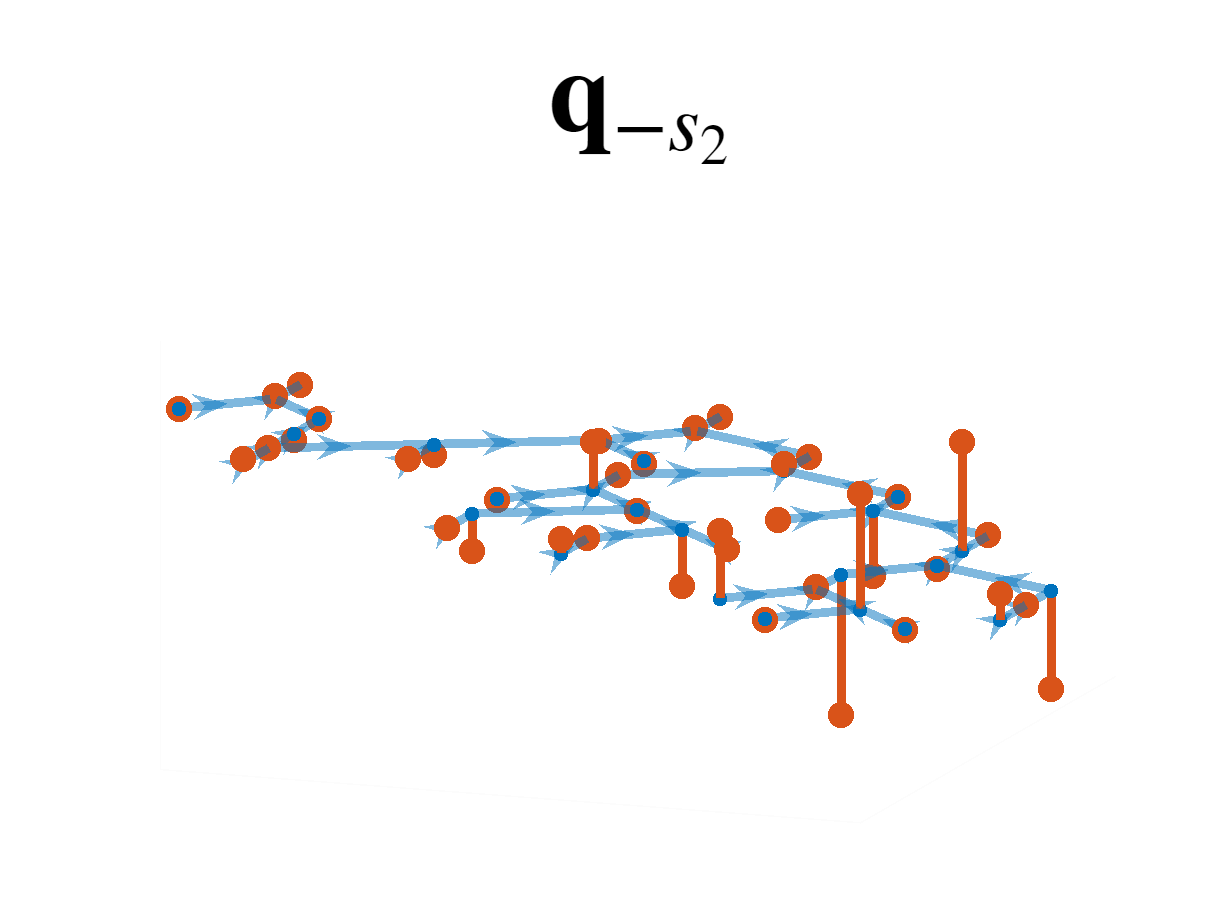

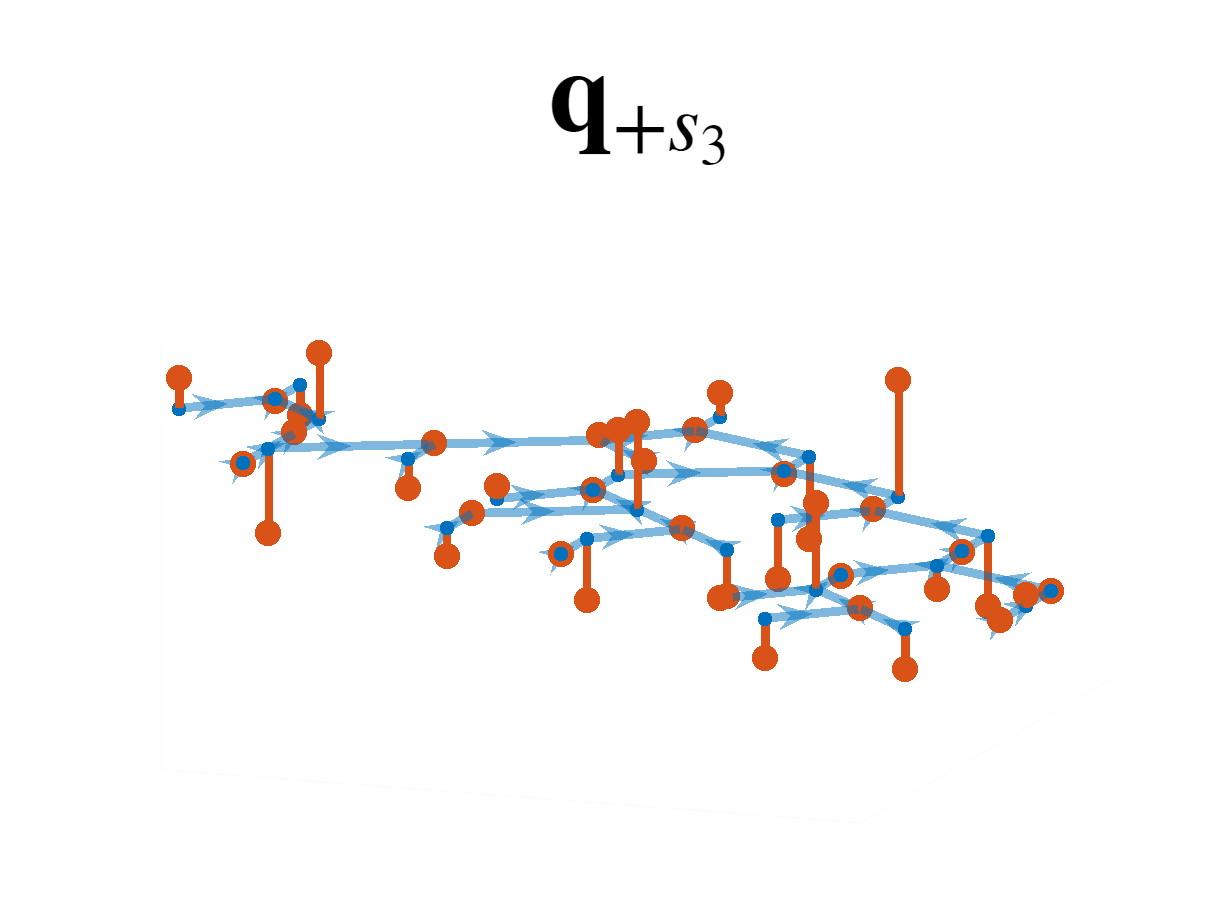

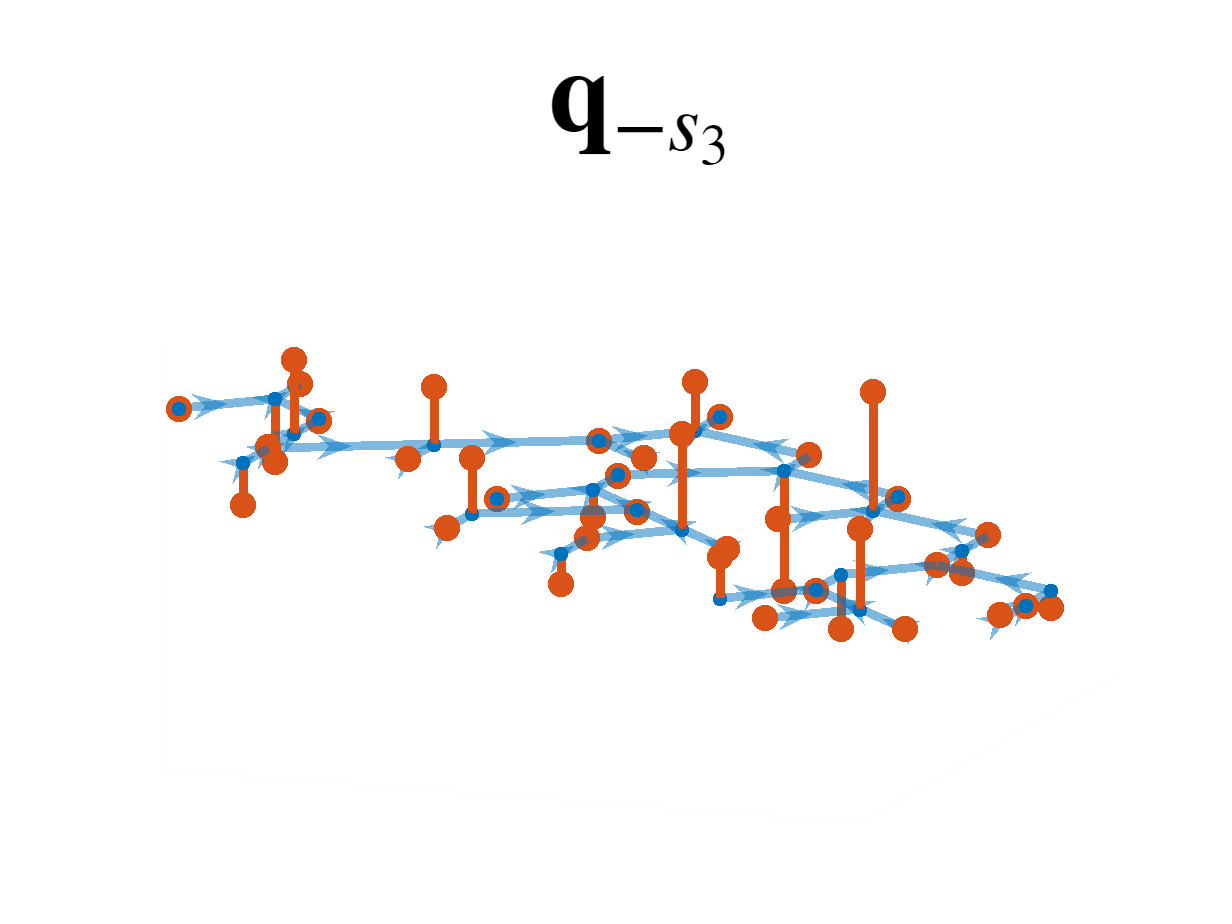

    locList ={'304031284401020','304031284401040','304031284401060','304031284401070','304031284401080',...
        '304031284401090','304031284401120','304031284401130','304031284401170','304031284401180',...
        '304031284401200','304031284403020','304031284403030','304031284403060','304031284403070',...
        '304031284403080','304031284403090','304031284403100','304031284403110','304031284403130',...
        '304031284403140','304031284403150','304031284404010','304031284404030','304031284404040',...
        '304031284404050','304031284404060','304031284416010','304031284416030','304031284416080',...
        '304031284416100','304031284416135','304031284416160','304031284416170','304031284416180',...
        '304031284416190','304031284416210','304031284419011','304031284419030','304031284420020'};


    Griver = digraph(Ariver,Triver,'omitselfloops');
    A = Ariver;
    G = Griver;

    lat = [37.6247,37.6375,37.6944,37.7839,37.8353,...
        37.8819,37.9406,37.5186,37.8219,37.5453,...
        37.6306,37.6636,37.6092,37.4481,37.3086,...
        37.2472,37.0958,36.9892,37.2419,37.2300,...
        37.1697,37.0617,37.1461,36.9528,36.9414,...
        36.9247,36.8694,36.2728,36.3697,36.5328,...
        36.7319,36.9172,36.2175,36.2869,36.3956,...
        36.6203,36.2672,37.0414,37.0528,36.5111,...
        ];

    long = [138.9097,138.9486,139.0342,139.0575,139.0619,...
        139.0144,139.0611,138.9292,139.0019,139.0881,...
        139.0958,138.7886,138.8419,138.8364,138.8008,...
        138.8031,138.7183,138.5858,138.9311,138.9567,...
        138.9272,138.8814,138.9958,138.9211,138.8142,...
        138.6456,138.8678,138.4186,138.2819,138.1119,...
        138.3094,138.3978,137.8708,137.9433,137.9267,...
        138.1417,137.9439,139.0611,138.9761,137.8158,...
        ];
end

figure
if isRiver
    h = plot(G,'LineWidth',4,'NodeLabel',TriverEng,'Layout','layered');

xLx = 67.9390 - 0.0000i


    h.XData = long;
    h.YData = lat;
    h.Interpreter = 'latex';
    h.NodeFontSize = 10;



ダウンロードサイト

- [https://www1.gsi.go.jp/geowww/globalmap-gsi/download/data/gm-japan/gm-jpn-all_u_2_2.zip](https://www1.gsi.go.jp/geowww/globalmap-gsi/download/data/gm-japan/gm-jpn-all_u_2_2.zip)

    coastl_jpn_file = "../data/gm-jpn-all_u_2_2/coastl_jpn.shp";

tv = 67.9390


    if ~exist(coastl_jpn_file,"file")
        coastl_jpn_url = "https://www1.gsi.go.jp/geowww/globalmap-gsi/download/data/gm-japan/gm-jpn-all_u_2_2.zip";
        %cdir = pwd;
        cdir = cd('../data');
        unzip(coastl_jpn_url)
        disp("Unzipped " + coastl_jpn_url)
        cd cdir;
    end
    CoastLine = shaperead('../data/gm-jpn-all_u_2_2/coastl_jpn.shp');
    mapshow(CoastLine,'LineWidth',1.5,'LineStyle',":",'Color',"black")
    title('DiGraph of Shinano River','Interpreter','latex')
    x_min = min(long);
    x_max = max(long);
    y_min = min(lat);
    y_max = max(lat);
    xlim([x_min-0.1 x_max+0.4])
    ylim([y_min-0.1 y_max+0.1])
    ax = gca;
    ax.FontSize = 11;
    hold off
    exportgraphics(ax,RESULTS_DIR+"DigraphShinano"+FIGEXT)
else
    h = plot(G,'LineWidth',4,'Layout','layered');
end


waterlevel =     7.6500    7.6500    7.6500    7.6500    7.6400    7.6400    7.6400    7.6300    7.6300    7.6200    7.6200    7.6600    7.7000    7.6700    7.6300    7.6200    7.5900    7.5900    7.6100    7.6300    7.6300    7.6400    7.6400    7.6400    7.6400    7.6500    7.6400    7.6400    7.6300    7.6300    7.6200    7.6200    7.6200    7.6200    7.6100    7.6200    7.6200    7.6200    7.6200    7.6200    7.6200    7.6200    7.6300    7.6400    7.6500    7.6500    7.6500    7.6500    7.6600    7.6600
    6.3000    6.3000    6.3000    6.2900    6.2900    6.2700    6.2700    6.2600    6.2800    6.3500    6.3200    6.3300    6.3500    6.3200    6.2700    6.2400    6.2100    6.2000    6.2200    6.2400    6.2600    6.2800    6.2800    6.2800    6.2800    6.2800    6.2800    6.2800    6.2600    6.2500    6.2400    6.2300    6.2200    6.2200    6.2200    6.2200    6.2200    6.2300    6.2300    6.2300    6.2300    6.2400    6.2500    6.2600    6.2800    6.2900    6.3000    6.3000    6.

if ~isDiGraph
    if isa(A,'digraph') || isa(A,'graph')

freqXSet = 1.0e+03 *

    1.1351    1.1352    1.1352    1.1352    1.1352    1.1352    1.1352    1.1352    1.1352    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1352    1.1352    1.1352    1.1352    1.1353    1.1353    1.1353    1.1353    1.1353    1.1353    1.1352    1.1352    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1351    1.1350    1.1351    1.1350
   -0.7974   -0.7974   -0.7974   -0.7973   -0.7973   -0.7973   -0.7972   -0.7972   -0.7972   -0.7972   -0.7971   -0.7971   -0.7971   -0.7971   -0.7970   -0.7970   -0.7970   -0.7970   -0.7970   -0.7971   -0.7971   -0.7972   -0.7972   -0.7973   -0.7973   -0.7973   -0.7973   -0.7973   -0.7972   -0.7972   -0.7972   -0.7972   -0.7972   -0.7972   -0.7972   -0.7972   -0.7972   -0.7971   -0.7971   -0.7971   -0.7971   -0.7971   -0.7970   -0.7971   -0.7971   -0.7971   -0.7971   -0.7

        A = adjacency(A);

y =     7.6500    7.6500    7.6500    7.6500    7.6400    7.6400    7.6400    7.6300    7.6300    7.6200    7.6200    7.6600    7.7000    7.6700    7.6300    7.6200    7.5900    7.5900    7.6100    7.6300    7.6300    7.6400    7.6400    7.6400    7.6400    7.6500    7.6400    7.6400    7.6300    7.6300    7.6200    7.6200    7.6200    7.6200    7.6100    7.6200    7.6200    7.6200    7.6200    7.6200    7.6200    7.6200    7.6300    7.6400    7.6500    7.6500    7.6500    7.6500    7.6600    7.6600
    6.3000    6.3000    6.3000    6.2900    6.2900    6.2700    6.2700    6.2600    6.2800    6.3500    6.3200    6.3300    6.3500    6.3200    6.2700    6.2400    6.2100    6.2000    6.2200    6.2400    6.2600    6.2800    6.2800    6.2800    6.2800    6.2800    6.2800    6.2800    6.2600    6.2500    6.2400    6.2300    6.2200    6.2200    6.2200    6.2200    6.2200    6.2300    6.2300    6.2300    6.2300    6.2400    6.2500    6.2600    6.2800    6.2900    6.3000    6.3000    6.3000    6

    end
    A = (A+A.')/2;
end

ans = 2.1326e-13

[U,Q,C,D,L,Lmd,Sgm] = fcn_digraphops(A)



y = ones(1,size(Lmd,2));

x_in =     7.6500    7.6500    7.6500    7.6500    7.6400    7.6400    7.6400    7.6300    7.6300    7.6200    7.6200    7.6600    7.7000    7.6700    7.6300    7.6200    7.5900    7.5900    7.6100    7.6300    7.6300    7.6400    7.6400    7.6400    7.6400    7.6500    7.6400    7.6400    7.6300    7.6300    7.6200    7.6200    7.6200    7.6200    7.6100    7.6200    7.6200    7.6200    7.6200    7.6200    7.6200    7.6200    7.6300    7.6400    7.6500    7.6500    7.6500    7.6500    7.6600    7.6600
    6.3000    6.3000    6.3000    6.2900    6.2900    6.2700    6.2700    6.2600    6.2800    6.3500    6.3200    6.3300    6.3500    6.3200    6.2700    6.2400    6.2100    6.2000    6.2200    6.2400    6.2600    6.2800    6.2800    6.2800    6.2800    6.2800    6.2800    6.2800    6.2600    6.2500    6.2400    6.2300    6.2200    6.2200    6.2200    6.2200    6.2200    6.2300    6.2300    6.2300    6.2300    6.2400    6.2500    6.2600    6.2800    6.2900    6.3000    6.3000    6.3000  

stem(diag(Lmd),y,'filled')

lmax = 3.0943

title('Graph frequencies (real part)','Interpreter','latex')
xlabel('$\lambda$','Interpreter','latex')

ax = gca;
ax.LineWidth = 2;
ax.FontSize = 16;

ans = 1×1 の cell 配列
    {@(x)regular(x*(2/lmax),d)}


exportgraphics(ax,RESULTS_DIR+"EigenValues_sym"+FIGEXT)

ans = 1×1 の cell 配列
    {@(x)real(sqrt(1-(regular(x*(2/lmax),d)).^2))}


sgm = sort([diag(Sgm,1);diag(Sgm,-1)],'ascend');
idxg = find(sgm);
gma = sgm(idxg);
if ~isempty(gma)
    y = ones(1,length(gma));
    stem(gma,y,'filled')
    title('Skew intensities (imaginary part)','Interpreter','latex')
    xlabel('$s$','Interpreter','latex')

    ax = gca;
    ax.LineWidth = 2;
    ax.FontSize = 16;
    exportgraphics(ax,RESULTS_DIR+"EigenValues_skw"+FIGEXT)
end

## $\;{\mathbf{u}}_{\lambda_k }$拡張GFT（対称成分）の基底ベクトル

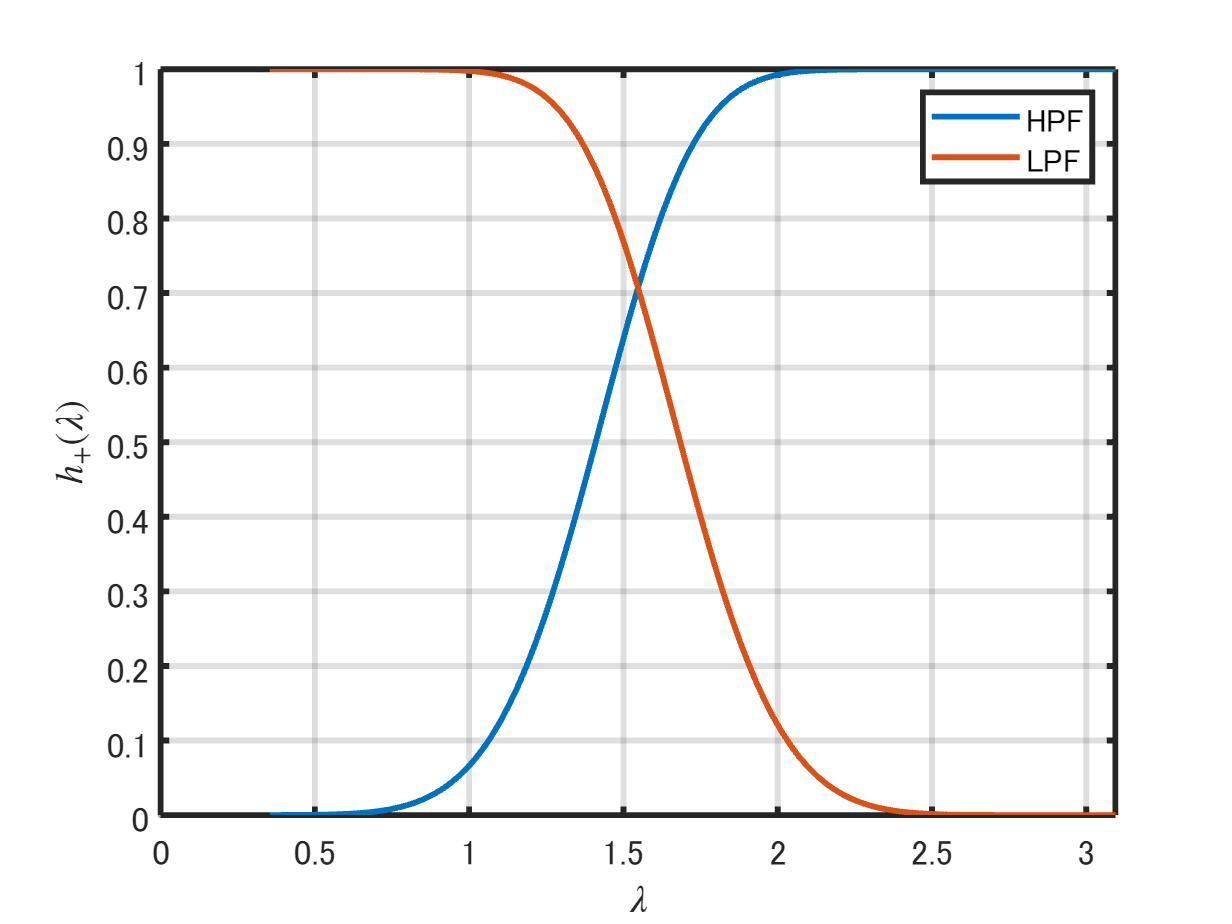

zscale = .8;
fontSize = 36;
lineWidth = 3;
arrowSize = 12;
az = 200;
el = 20;
for k = 0:5

    figure
    %uk = U(:,k+1)*Lmd(k+1,k+1);
    uk = U(:,k+1);
    %
    p1 = plot(G,'LineWidth',lineWidth);
    p1.ArrowSize = arrowSize;
    p1.NodeLabel = {};
    hold on
    stem3(p1.XData,p1.YData,uk,'fill','LineWidth',lineWidth);
    %zlim(zscale*[-1 1])
    %axis off
    title("$\mathbf{u}_{\lambda_"+num2str(k)+"}$",'Interpreter','latex','FontSize',20)
    view(az,el)
    hold off
    ax = gca;
    ax.FontSize = fontSize;
    ax.ZLim = zscale*[-1 1];
    ax.Box = 'off';
    ax.XColor = .99*[1 1 1];
    ax.YColor = .99*[1 1 1];
    ax.ZColor = .99*[1 1 1];
    ax.XLim = [2 7];
    ax.YLim = [2 12];
    ax.Clipping = 'off';
    exportgraphics(ax,RESULTS_DIR+"u"+num2str(k)+FIGEXT)
end

## $\;{\mathit{\mathbf{q}}}_{s_k }$拡張GFT（交代成分）の基底ベクトル

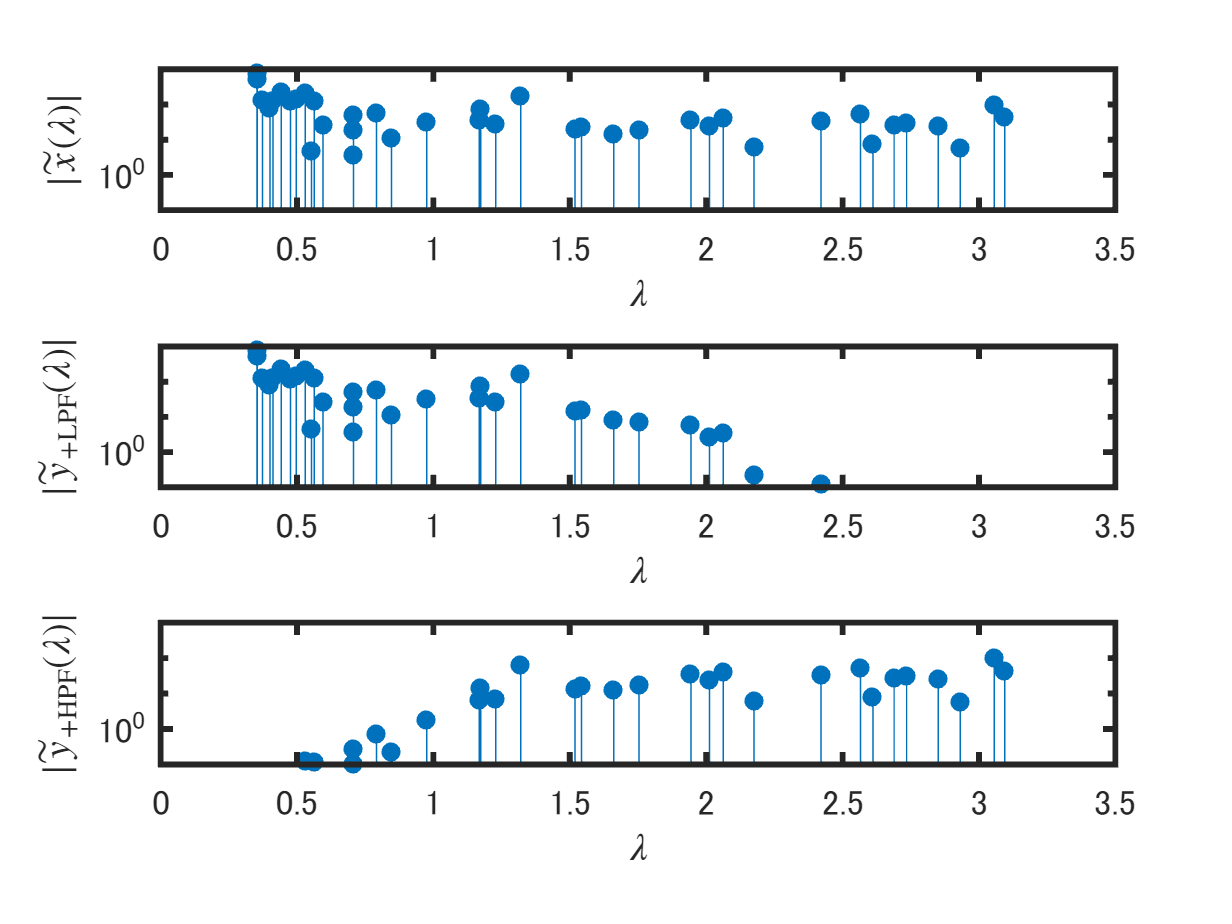

for k = 0:min(5,length(gma)/2-1)
    figure
    qkp = Q(:,2*k+1);
    % +sk
    p1 = plot(G,'LineWidth',lineWidth);
    p1.ArrowSize = arrowSize;
    p1.NodeLabel = {};
    hold on
    stem3(p1.XData,p1.YData,qkp,'fill','LineWidth',lineWidth);
    title("$\mathbf{q}_{+s_"+num2str(k)+"}$",'Interpreter','latex','FontSize',20)
    view(az,el)
    hold off
    ax = gca;
    ax.FontSize = fontSize;
    ax.ZLim = zscale*[-1 1];
    ax.Box = 'off';
    ax.XColor = .99*[1 1 1];
    ax.YColor = .99*[1 1 1];
    ax.ZColor = .99*[1 1 1];
    ax.XLim = [2 7];
    ax.YLim = [2 12];
    ax.Clipping = 'off';
    exportgraphics(ax,RESULTS_DIR+"qp"+num2str(k)+FIGEXT)

    %
    figure
    qkm = Q(:,2*k+2);
    % -sk
    p1 = plot(G,'LineWidth',lineWidth);
    p1.ArrowSize = arrowSize;

ans = 1.7761e+06

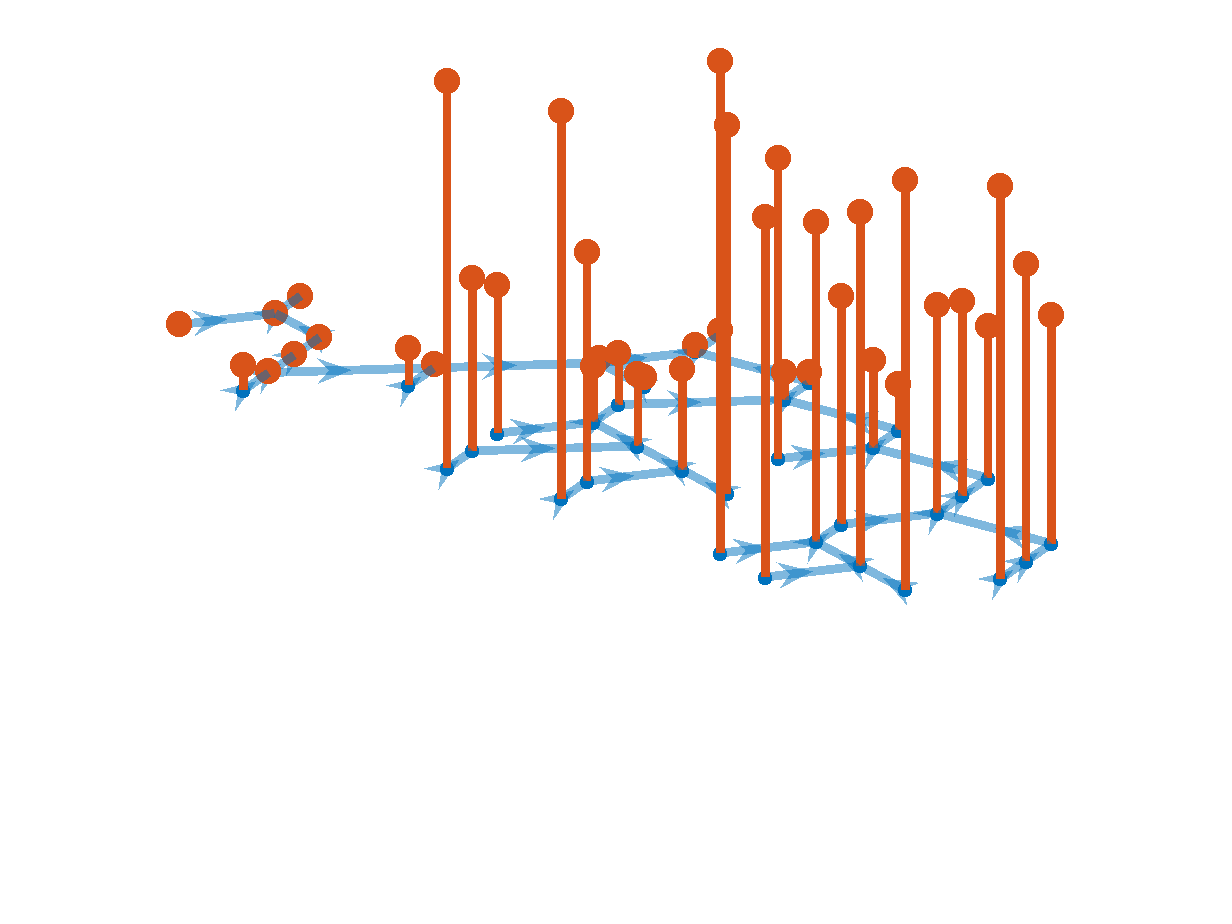

    p1.NodeLabel = {};
    hold on

HMode: lowpass


ans = 1.6142e+06

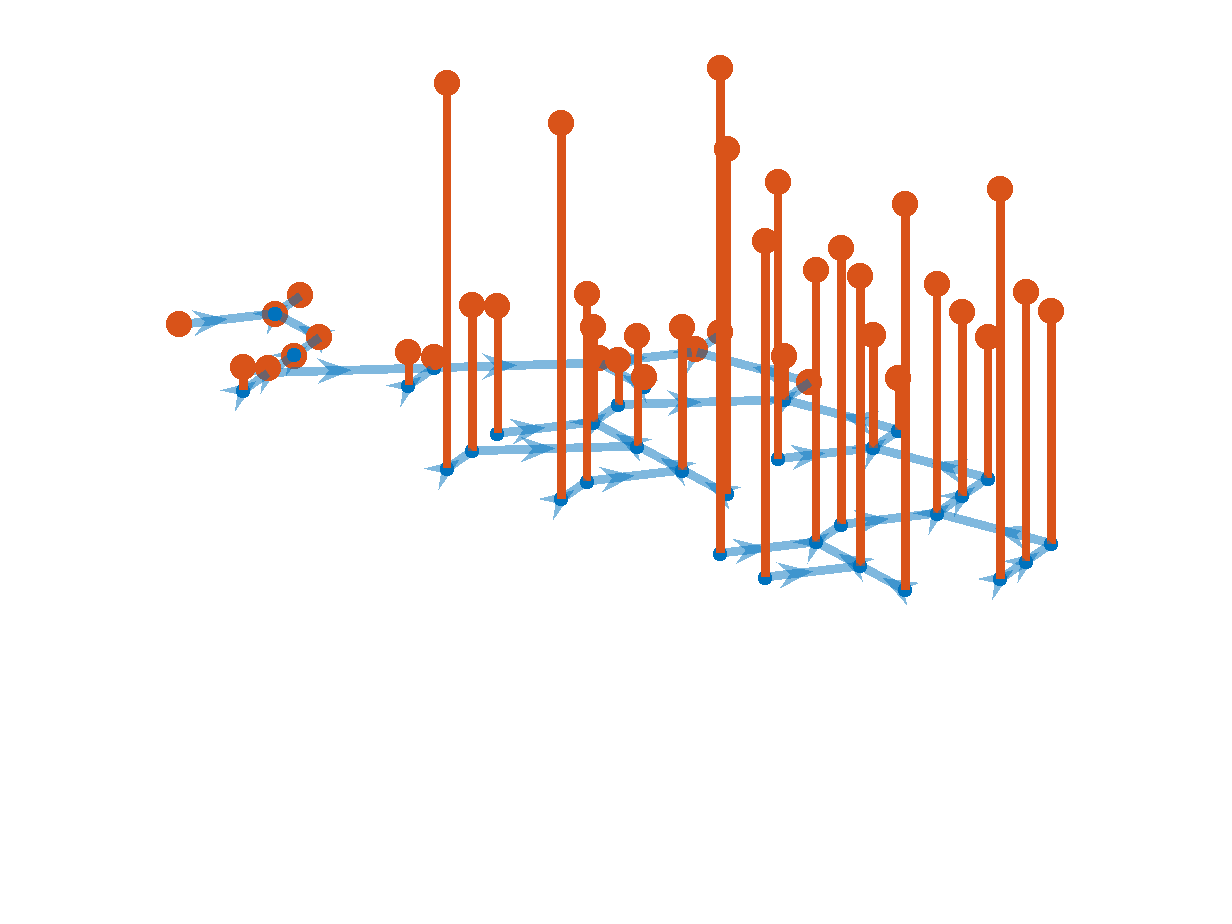

HMode: highpass


ans = 9.5854e+04

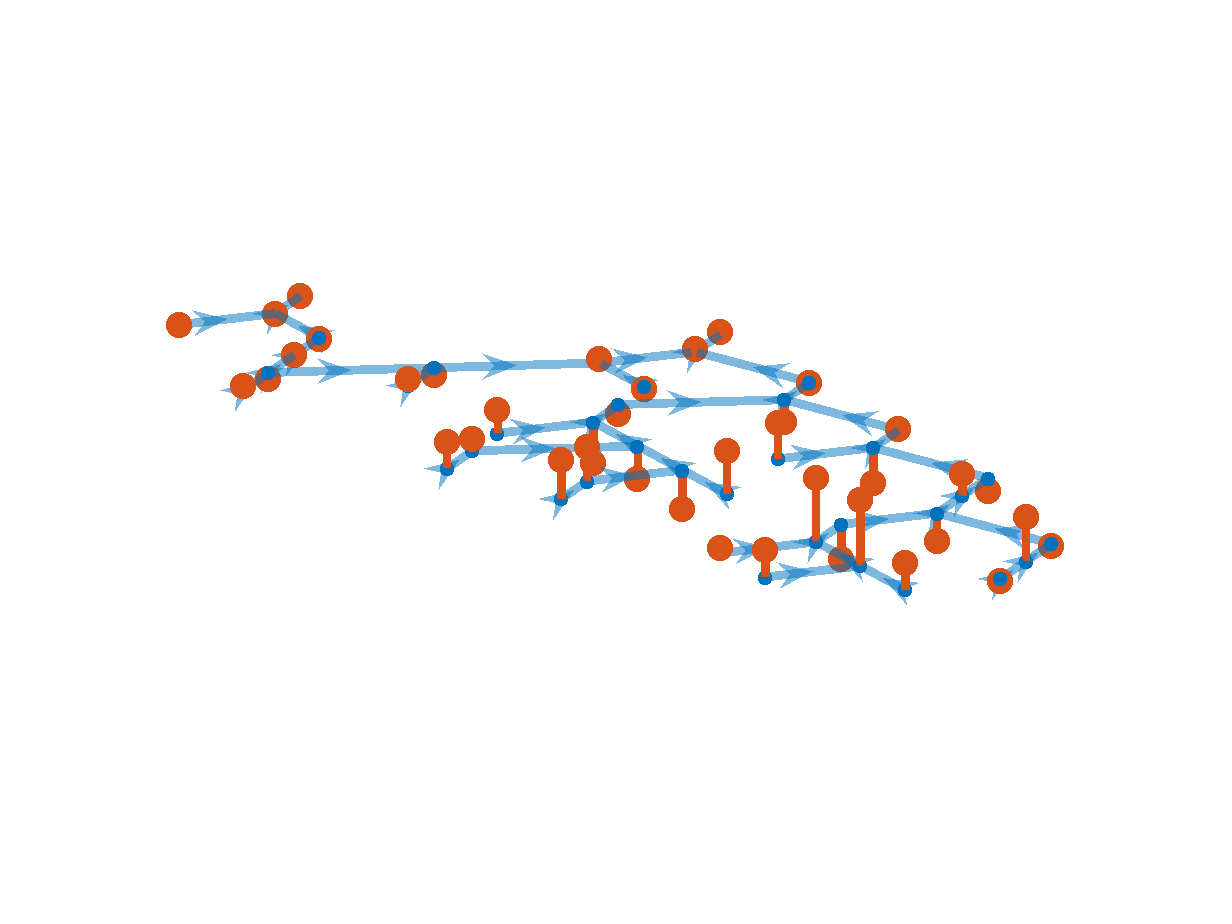

    stem3(p1.XData,p1.YData,qkm,'fill','LineWidth',lineWidth);
    title("$\mathbf{q}_{-s_"+num2str(k)+"}$",'Interpreter','latex','FontSize',20)
    view(az,el)
    hold off
    ax = gca;
    ax.FontSize = fontSize;
    ax.ZLim = zscale*[-1 1];
    ax.Box = 'off';
    ax.XColor = .99*[1 1 1];
    ax.YColor = .99*[1 1 1];
    ax.ZColor = .99*[1 1 1];
    ax.XLim = [2 7];
    ax.YLim = [2 12];
    ax.Clipping = 'off';
    exportgraphics(ax,RESULTS_DIR+"qm"+num2str(k)+FIGEXT)
    %
end

## 
$$\;$$


## 変動の確認


$$\mathbf{L}=\left(\begin{array}{cccc}
d_{11} & -b_{12} & -b_{13} & -b_{14}\\
-\bar{b}_{12} & d_{22} & -b_{23} & -b_{24}\\
-\bar{b}_{13} & -\bar{b}_{23} & d_{33} & -b_{34}\\
-\bar{b}_{14} & -\bar{b}_{24} & -\bar{b}_{34} & d_{44}
\end{array}\right)$$



$$\underbrace{\left(\begin{array}{c}
y_{1}\\
y_{2}\\
y_{3}\\
y_{4}
\end{array}\right)}_{\mathbf{y}}=\underbrace{\left(\begin{array}{cccc}
d_{11} & -b_{12} & -b_{13} & -b_{14}\\
-\bar{b}_{12} & d_{22} & -b_{23} & -b_{24}\\
-\bar{b}_{13} & -\bar{b}_{23} & d_{33} & -b_{34}\\
-\bar{b}_{14} & -\bar{b}_{24} & -\bar{b}_{34} & d_{44}
\end{array}\right)}_{\mathbf{L}}\underbrace{\left(\begin{array}{c}
x_{1}\\
x_{2}\\
x_{3}\\
x_{4}
\end{array}\right)}_{\mathbf{x}}$$



$$d_{k,k}:=\sum_{\ell\in\mathcal{N}\backslash \{k\}} |c_{k,\ell}|=\sum_{\ell\in\mathcal{N}\backslash \{k\}}  |c_{\ell,k}|=\sum_{\ell\in\mathcal{N}\backslash \{k\}}  \sqrt{c_{k,\ell}b_{\ell,k}}=\sum_{\ell\in\mathcal{N}\backslash \{k\}}  \sqrt{c_{k,\ell}\bar{c}_{k,\ell}}

$$


ただし， $\mathcal{N}:=\{1,2,\cdots,N\}$。


$$y_{k}=d_{k,k}x_k-\sum_{\ell=k+1}^{N} b_{k,\ell}x_\ell-\sum_{\ell=1}^{k-1} \bar{b}_{k,\ell}x_\ell$$



$$\Delta_{\mathbf{L}}(\mathbf{x})=\mathbf{x}^T\mathbf{L}\mathbf{x}=\sum_{k\in\mathcal{N}}\sum_{\ell=k+1}^N |b_{k,\ell}|\cdot|x_k-e^{-j\angle b_{k,\ell}} x_\ell|^2$$


行列計算

nDims = size(L,1);
x = randn(nDims,1);
xLx = x.'*L*x

累積加算

tv = 0;
for iRow = 1:nDims
    xk = x(iRow);
    for iCol = iRow+1:nDims
        ckl = C(iRow,iCol);
        xl = x(iCol);
        tv = tv + abs(ckl)*abs(xk-exp(1j*angle(ckl))*xl)^2;
    end
end
tv

誤差評価

assert(abs(xLx - tv)<1e-6,'Invalid TV')

HpMode: lowpass


- HmMode: zeros


cost = 5.5735e+05

ans = 5.5735e+05

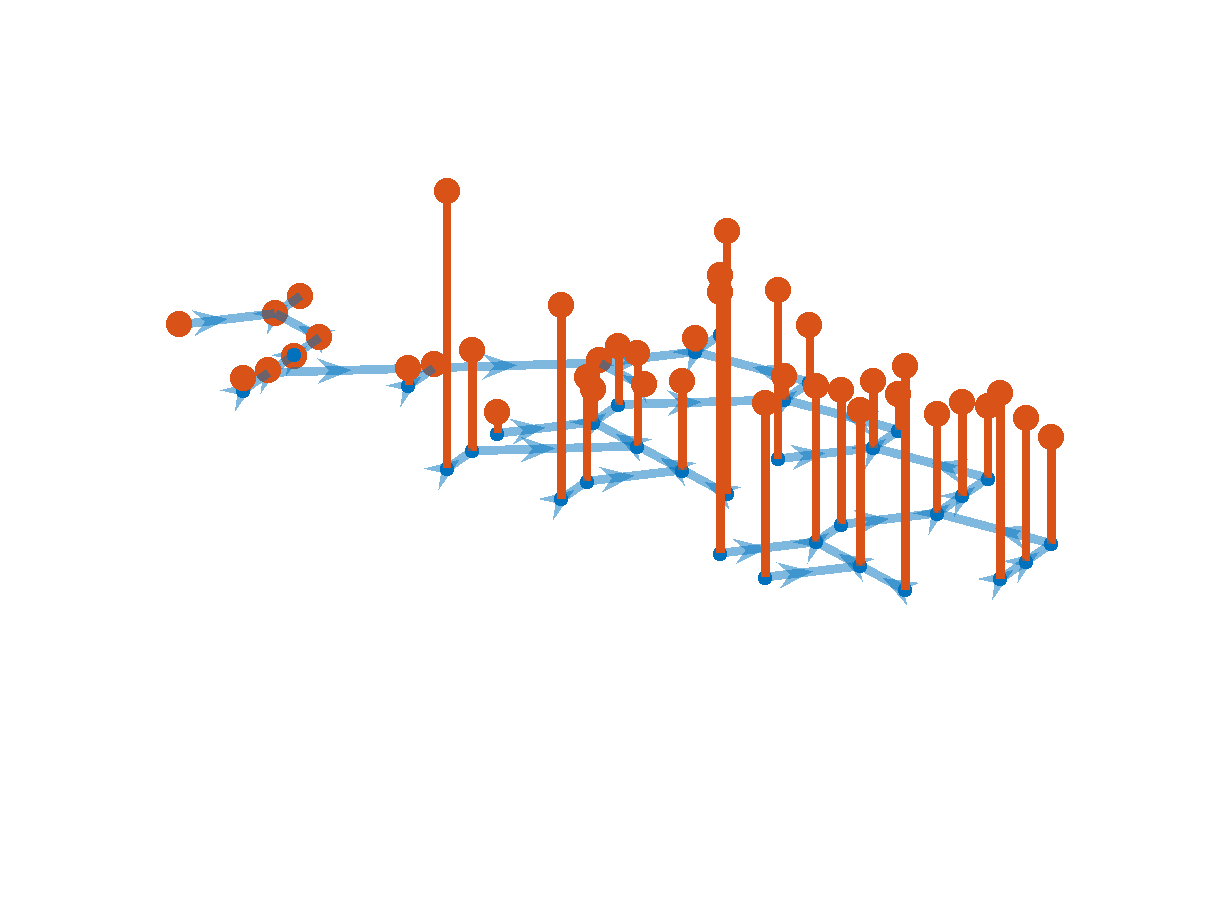

ans = 5.5691e+05

MultiStart は、すべての開始点からの実行を完了しました。 

20 回すべてのローカル ソルバーの実行が、ローカル ソルバーの正の終了フラグで収束しました。


- HmMode: opts


cost = 5.3849e+05

ans = 5.3849e+05

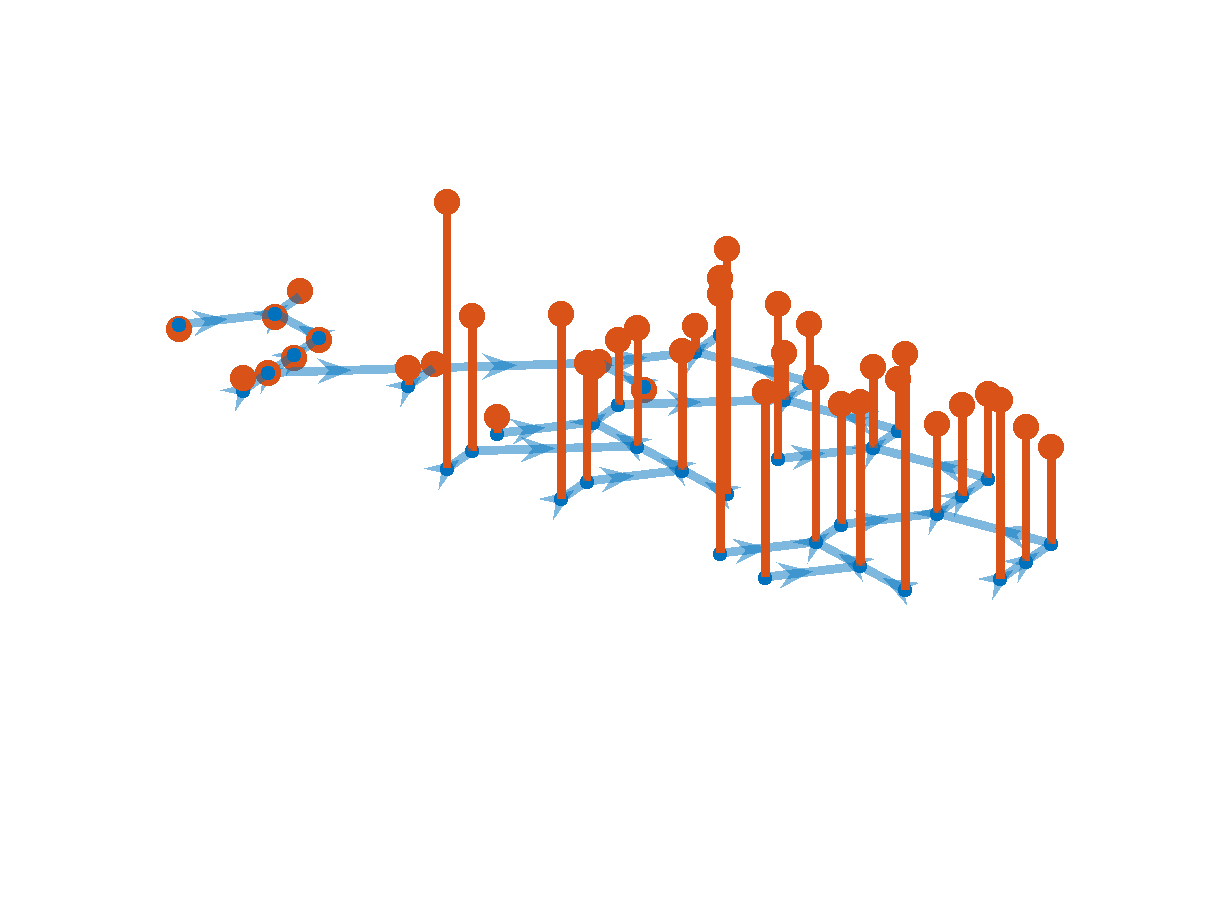

HpMode: highpass


- HmMode: zeros


cost = 4.1275e+04

ans = 4.1275e+04

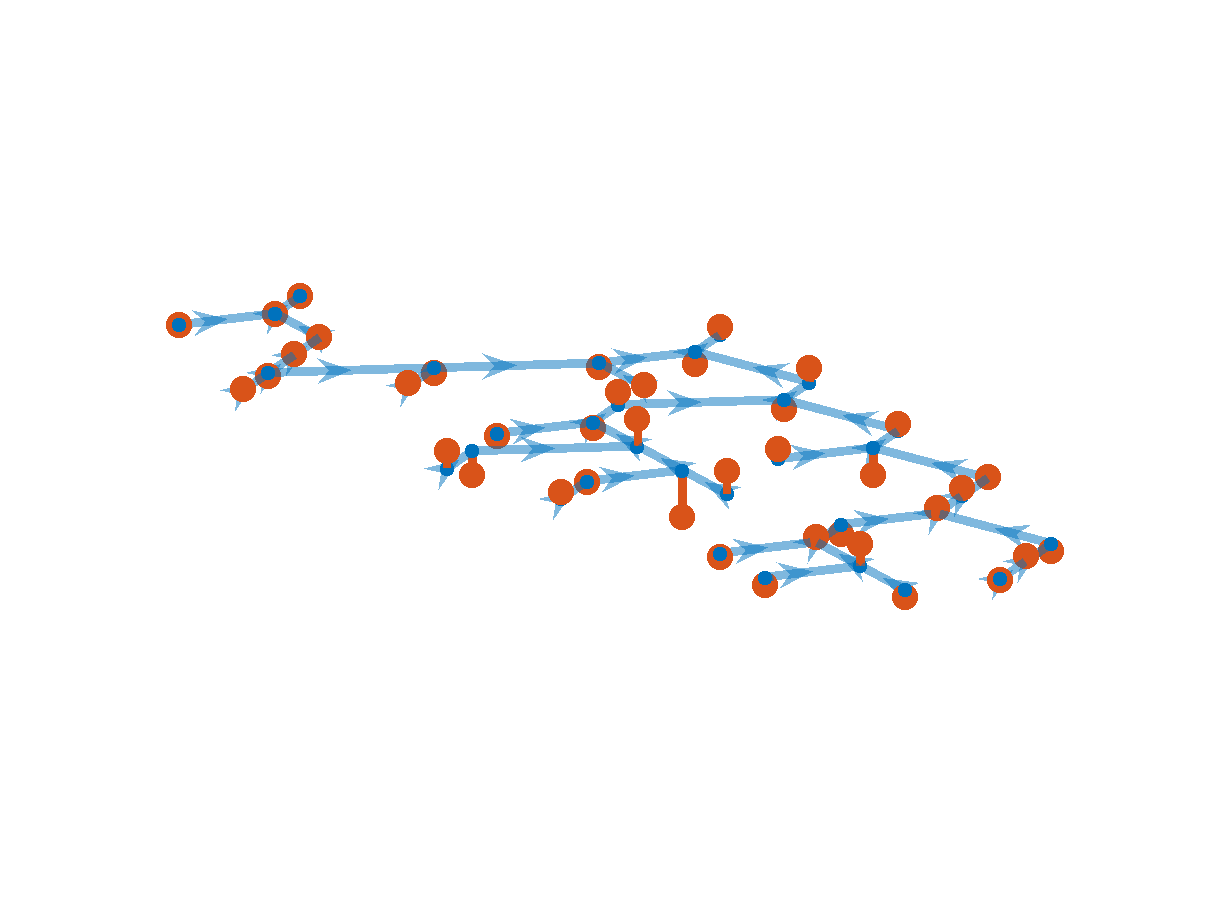

ans = 4.1184e+04

MultiStart は、すべての開始点からの実行を完了しました。 

20 回すべてのローカル ソルバーの実行が、ローカル ソルバーの正の終了フラグで収束しました。


- HmMode: opts


cost = 2.2190e+04

ans = 2.2190e+04

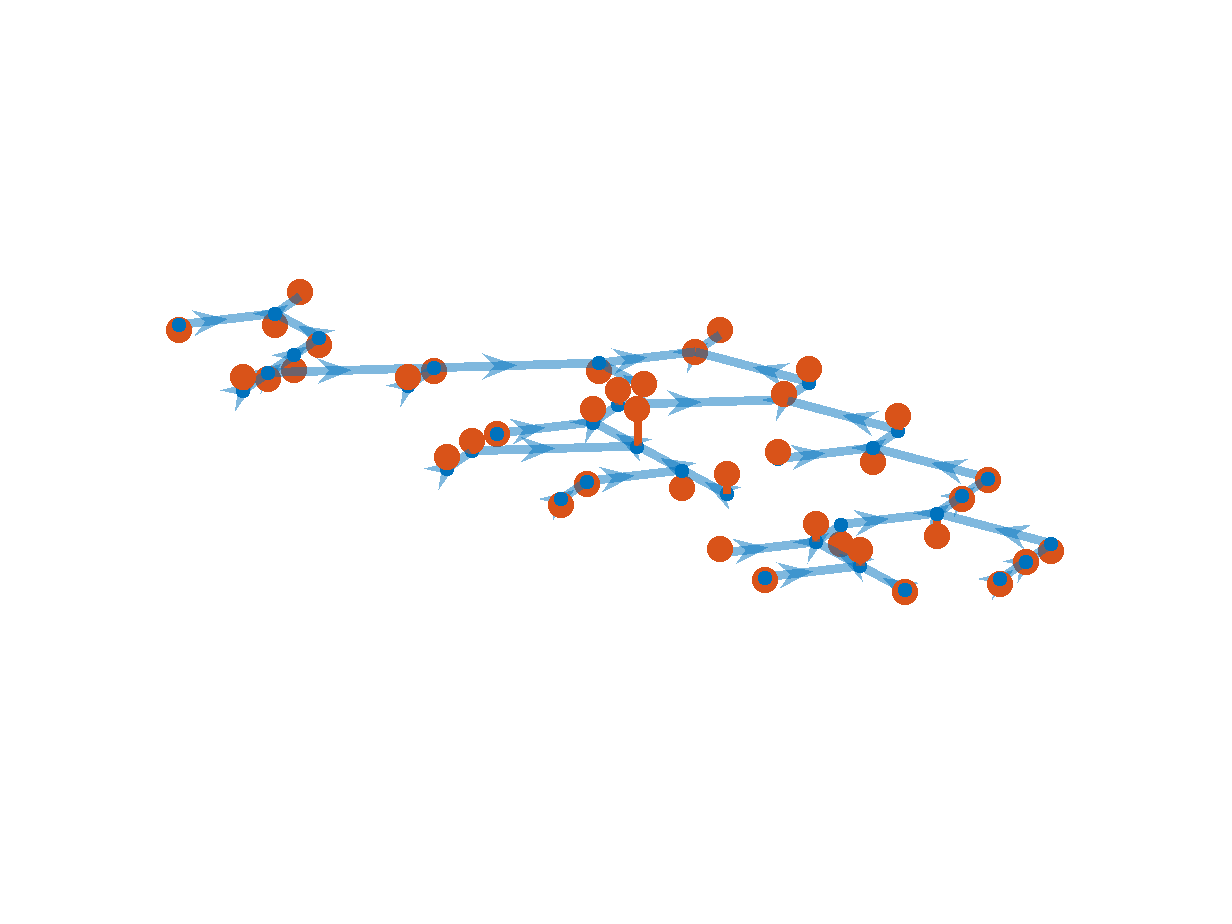

if isRiver
    %解析期間設定
    year = "2022";
    month1 = "0801";
    num_day1 = 31; % month1が何日間か指定(最新のデータで月の途中の場合なども可)

    bgn_day =1; % 解析開始日
    bgn_time =1; %解析開始時間

    end_day =5 ;% 解析終了日(月をまたぐ場合はまたぐ場合の日付)
    end_time =24;%解析終了時間

    %月をまたぐ場合の機能　
    pathmonth = 0; %月をまたぐ場合は1に設定
    month2 = "0401"; %month1 の次の月を指定
    num_day2 = 31;%month2が何日までなのか指定

    errorcatch1 = "終了時間の方が開始時間よりも前にあります！";
    errorcatch2 = "minがmaxよりも大きいです";


    % error message
    if pathmonth == 0
        if bgn_day*24+bgn_time > end_day*24+end_time
            errorcatch1
        end
    end

    er_month1 = erase(month1,'01');
    er_month1 = str2double(er_month1);
    er_month2 = erase(month2,'01');
    er_month2 = str2double(er_month2);

    BGN = (bgn_day-1)*24+(bgn_time-1);

    if pathmonth == 1
        END = (num_day1*24) + (end_day-1)*24 + end_time;
    else
        END = (end_day-1)*24 + end_time;
    end

    hours = END - BGN;


    if hours < 0
        errorcatch1
    end

    formatSpec = 'Start: %d/%d %d:00, Finish: %d/%d %d:00, Time: %d hours';
    if pathmonth == 0
        DATA_period = sprintf(formatSpec,er_month1,bgn_day,bgn_time,er_month1,end_day,end_time,hours);
    else
        DATA_period = sprintf(formatSpec,er_month1,bgn_day,bgn_time,er_month2,end_day,end_time,hours);
    end

    % ana_hours = 35 %round(hours*30/100)
    t_duration = hours + 1;

データ収集

    str1 = "http://www1.river.go.jp/cgi-bin/DspWaterData.exe?KIND=2&ID=";
    bg = "&BGNDATE=";
    en = "&ENDDATE=";
    str2 = "&KAWABOU=NO";
    enddate = "1231"; % ここは変更しない　絶対触るな
    check = "0000ff"; %暫定値の時でも抽出できる用（絶対消すな）
    % check2 = "｡｡"
    error1 = "#ff00ff"; %閉局・欠測も抽出できる用（絶対消すな）
    options = weboptions('CharacterEncoding','Shift_JIS');

    locs =40;
    waterlevel1 = zeros(num_day1*24,locs);
    waterlevel2 = zeros(num_day2*24,locs);

    for iloc = 1:locs
        ID = locList(iloc);
        url1 = str1 + ID + bg + year + month1 + en + year + enddate + str2;
        response1 = string(webread(url1,options));
        response1 = extractBetween(response1,'<TBODY>','</TBODY>');
        response1 = extractAfter(response1,'<TH bgcolor="#AAFFAA">');

        if contains(response1,check) == 1
            response1 = extractBetween(response1,'<FONT size="-1" color=','</FONT>');
            response1 = extractAfter(response1,'>');

        else
            response1 = extractAfter(response1,'</TR>');
            response1 = extractBetween(response1,'<TD align="','</FONT></TD>');
            response1 = extractAfter(response1,'<FONT size="-1">');
        end

        waterlevel1(:,iloc) = response1;

    end
    waterlevel1 = transpose(waterlevel1);
    waterlevel1 = fillmissing(waterlevel1,'linear',2,'EndValues','nearest');
    %　月を跨いで解析するよう（エラーの原因がわからないので保留）最悪if文無くして配列結合して処理する
    if pathmonth == 1
        for iloc = 1:locs
            ID = locList(iloc);
            url2 = str1 + ID + bg + year + month2 + en + year + enddate + str2;
            response2 = string(webread(url2,options));
            response2 = extractBetween(response2,'<TBODY>','</TBODY>');
            response2 = extractAfter(response2,'<TH bgcolor="#AAFFAA">');

            if contains(response2,check) == 1
                response2 = extractBetween(response2,'<FONT size="-1" color=','</FONT>');
                response2 = extractAfter(response2,'>');
            else
                response2 = extractAfter(response2,'</TR>');
                response2 = extractBetween(response2,'<TD align="','</FONT></TD>');
                response2 = extractAfter(response2,'<FONT size="-1">');
            end

            % 欠損データ補間(NaNの場合に直前のデータと同じにする)
            response2 = fillmissing(response2,"previous");

            waterlevel2(:,iloc) = response2;
        end
        waterlevel2 = transpose(waterlevel2);
        waterlevel2 = fillmissing(waterlevel2,'linear',2,'EndValues','nearest')
    end

    if pathmonth == 12
        waterlevel = cat(2,waterlevel1,waterlevel2);
    else
        waterlevel = waterlevel1;
    end

    %ゼロ点高足し合わせ(水文水質データベースより)
    %%{
    waterlevel(8,:)=waterlevel(8,:)+14.800;
    waterlevel(10,:)=waterlevel(10,:)+58.5;
    waterlevel(11,:)=waterlevel(11,:)+39.9;
    waterlevel(23,:)=waterlevel(23,:)+232.0;
    waterlevel(24,:)=waterlevel(24,:)+575.577;
    waterlevel(25,:)=waterlevel(25,:)+357.495;
    waterlevel(26,:)=waterlevel(26,:)+468.000;
    waterlevel(27,:)=waterlevel(27,:)+604.213;
    waterlevel(28,:)=waterlevel(28,:)+610.870;
    waterlevel(29,:)=waterlevel(29,:)+463.600;
    waterlevel(30,:)=waterlevel(30,:)+355.950;
    waterlevel(31,:)=waterlevel(31,:)+324.255;
    waterlevel(32,:)=waterlevel(32,:)+300.480;
    waterlevel(33,:)=waterlevel(33,:)+640.130;
    waterlevel(34,:)=waterlevel(34,:)+550.010;
    waterlevel(35,:)=waterlevel(35,:)+498.570;
    waterlevel(36,:)=waterlevel(36,:)+360.120;
    waterlevel(37,:)=waterlevel(37,:)+560.880;
    waterlevel(38,:)=waterlevel(38,:)+601.850;
    waterlevel(39,:)=waterlevel(39,:)+269.420;
    waterlevel(40,:)=waterlevel(40,:)+765.000;
    %%}
    % 解析期間を設定してデータを成型
    waterlevel(:,END+1:end) = [];
    waterlevel(:,1:BGN) = []
else
    waterlevel = randn(nDims)
end

x = waterlevel;
freqXSet = fcn_fwdAuGFT(x,U,Q)
y = fcn_invAuGFT(freqXSet,U,Q)

rmse = @(rx,ry) norm(rx(:)-ry(:),2)/sqrt(numel(rx));
rmse(waterlevel,y)
assert(norm(x(:)-y(:))<1e-6)

### フィルタ処理実験

x_in = waterlevel
lmax = max(diag(Lmd))
g_dr = gsp_design_regular(lmax);
G_A = 1.0;
G_B = 1.0;

HPF LPF 関数表示,抽出

g_dr(1) % HPF
g_dr(2) % LPF
lambdas = linspace(Lmd(1),lmax);
fd_H = gsp_filter_evaluate(g_dr(1),lambdas);
fd_L = gsp_filter_evaluate(g_dr(2),lambdas);
figure
plot(lambdas,fd_H,'LineWidth',2)
xlim(full([0 lmax]));
xlabel('$\lambda$','Interpreter','latex','FontSize',12)
ylabel('$h_{+}(\lambda)$','Interpreter','latex','FontSize',12)
%title('HPF')
hold on

%figure
plot(lambdas,fd_L,'LineWidth',2)
xlim(full([0 lmax]));
hold off
grid on
ax = gca;
legend({'HPF','LPF'})
ax.LineWidth = 2;
ax.FontSize = 12;
exportgraphics(ax,RESULTS_DIR+"filterbank"+FIGEXT)

ylim_ = [0.1 1000];

lambdaList = diag(Lmd);
filterList_high = gsp_filter_evaluate(g_dr(1),lambdaList);
H_high = filterList_high; % Rename
filterList_low = gsp_filter_evaluate(g_dr(2),lambdaList);
H_low = filterList_low; % Rename

jikoku = min(90,size(freqXSet,2));
N = length(lambdaList);
freqX = freqXSet(:,jikoku);
freqY_high = diag(H_high)*freqX(1:N,:);
freqY_low  = diag(H_low)*freqX(1:N,:);

%スペクトル
figure
subplot(3,1,1)
stem(lambdaList,abs(freqX(1:N,:)),'Filled')
xlabel('$\lambda$','Interpreter','latex')
ylabel('$|\tilde{x}(\lambda)|$','Interpreter','latex')
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 2;
ax.YScale = 'log';
ax.YLim = ylim_;
exportgraphics(ax,RESULTS_DIR+"X"+FIGEXT)

subplot(3,1,2)
stem(lambdaList,abs(freqY_low),'filled')
xlabel('$\lambda$','Interpreter','latex')
ylabel('$|\tilde{y}_\mathrm{+LPF}(\lambda)|$','Interpreter','latex')
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 2;
ax.YScale = 'log';
ax.YLim = ylim_;
exportgraphics(ax,RESULTS_DIR+"Ylpf"+FIGEXT)

subplot(3,1,3)
stem(lambdaList,abs(freqY_high),'filled')
xlabel('$\lambda$','Interpreter','latex')
ylabel('$|\tilde{y}_\mathrm{+HPF}(\lambda)|$','Interpreter','latex')
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 2;
ax.YScale = 'log';
ax.YLim = ylim_;
exportgraphics(ax,RESULTS_DIR+"Yhpf"+FIGEXT)

% x
x_in = waterlevel(:,jikoku);
xSet = waterlevel;
y = x_in;
real(y.'*L*y)
yfile = "orig";
mygstem3(G, x_in, RESULTS_DIR, yfile, FIGEXT);

### ユニタリGFT(ParaGFT)による処理

[W,~,~,~,~,paraLmd] = fcn_paragraphops(A);
paraH_high = gsp_filter_evaluate(g_dr(1),diag(paraLmd));
paraH_low = gsp_filter_evaluate(g_dr(2),diag(paraLmd));
%
hModeSet = {  'lowpass', 'highpass'}; % 'direct',
for idxHMode = 1:length(hModeSet)
    hMode = hModeSet{idxHMode};
    if strcmp(hMode,'direct')
        hp = ones(N,1);
    elseif strcmp(hMode,'lowpass')
        hp = paraH_low;
    elseif strcmp(hMode,'highpass')
        hp = paraH_high;
    else
        error('Invalide HMode')
    end
    disp("==========")
    disp("HMode: " + hMode)
    % y
    y = real(W*(hp.*W')*x_in); % 実部を抽出
    real(y.'*L*y)
    yfile = "y_h_" + hMode + "_paragft";
    mygstem3(G, y, RESULTS_DIR, yfile, FIGEXT);
end



hpModeSet = {'lowpass', 'highpass'};
hmModeSet = { 'zeros', 'opts' };
r = size(Q,2);
sc = 1; %sqrt(2); % h+ フィルタ利得

for idxHpMode = 1:length(hpModeSet)
    hpMode = hpModeSet{idxHpMode};
    if strcmp(hpMode,'direct')
        hp = ones(N,1);
    elseif strcmp(hpMode,'lowpass')
        hp = sc*H_low;
    elseif strcmp(hpMode,'highpass')
        hp = sc*H_high;
    else
        error('Invalide HpMode')
    end
    disp("==========")
    disp("HpMode: " + hpMode)

    for idxHmMode = 1:length(hmModeSet)
        if r == 0
            warning('HmMode N/A')
        else
            hmMode = hmModeSet{idxHmMode};
            if strcmp(hmMode,'zeros')
                hm = zeros(r/2,1);
            elseif strcmp(hmMode,'ones')
                hm = ones(r/2,1);
            elseif strcmp(hmMode,'negones')
                hm = -ones(r/2,1);
            elseif strcmp(hmMode,'opts')
                hm0 = zeros(r/2,1);
                rng default % For reproducibility
                opts = optimoptions(@fminunc);
                mycost_(hp,hm0,U,Q,L,xSet)
                problem = createOptimProblem('fminunc',...
                    'objective', @(hm) mycost_(hp,hm,U,Q,L,xSet),... % 最適はデータセットを使うように変更
                    'x0',hm0,'options',opts);
                ms = MultiStart;
                hm = run(ms,problem,20);
            else
                error('Invalid HmMode')
            end
        end
        disp("- HmMode: "+hmMode)
        cost = mycost_(hp,hm,U,Q,L,x_in)
        %

        % y
        y = myfilt_(x_in,hp,hm,U,Q);
        real(y.'*L*y)
        yfile = "y_hp_" +hpMode+"_hm_" + hmMode;
        mygstem3(G, y, RESULTS_DIR, yfile, FIGEXT);

    end

end

### 自作関数:グラフ信号の可視化

function mygstem3(G, y, RESULTS_DIR, yfile,FIGEXT)
zscale = 400;
fontSize = 36;
lineWidth = 3;
arrowSize = 12;
az = 200;
el = 20;
%
figure
p1 = plot(G,'LineWidth',lineWidth);
p1.ArrowSize = arrowSize;
p1.NodeLabel = {};
hold on
stem3(p1.XData,p1.YData,y,'fill','LineWidth',lineWidth);
axis off
view(az,el)
hold off
ax = gca;
%
ax.FontSize = fontSize;
ax.ZLim = zscale*[-1 1];
ax.Box = 'on';
ax.XColor = .99*[1 1 1];
ax.YColor = .99*[1 1 1];
ax.ZColor = .99*[1 1 1];
ax.XLim = [2 7];
ax.YLim = [2 12];
ax.Clipping = 'off';
%
exportgraphics(ax,RESULTS_DIR+yfile+FIGEXT)
end

function cost =  mycost_(hp,hm,U,Q,L,x)
y = myfilt_(x,hp,hm,U,Q);
v = L*y;
cost = 0;
for idx = 1:size(v,2)
    cost = cost + real(y(:,idx)'*v(:,idx));
end
cost = cost/size(v,2);
end

function y = myfilt_(x,hp,hm,U,Q)
N = size(x,1);
r = size(Q,2);
freqX = fcn_fwdAuGFT(x,U,Q);
freqXp = freqX(1:N,:);
freqYp = hp.*freqXp;
freqXm = freqX(N+1:end,:);
%
if r == 0
    freqYm = [];
else
    tmp = [1 0 ; -1 0]*ones(2,r/2)*diag(hm); % FIXME: h_(Σ)
    tmp = upsample(tmp.',2).';
    tmp = tmp(:,1:end-1);
    h_Sgm = diag(tmp(1,:),1)+diag(tmp(2,:),-1);
    freqYm = h_Sgm * freqXm; % TODO: h_Sgm
end
%
freqY = vertcat(freqYp,freqYm);
y = fcn_invAuGFT(freqY,U,Q);

end